% Initializing script
clc, clf, clear

constants;

% Design space for optimization
n_data = 10;    % number of data points
P_c = linspace(0.5*P_c_ref, 1.5*P_c_ref, n_data); % chamber pressure range (Pa)
A_t = linspace(0.5*A_t_ref, 1.5*A_t_ref, n_data); % throat area range (m2)
A_e = linspace(0.5*A_e_ref, 1.5*A_e_ref, n_data); % exit area range (m2)

## Convexity analysis

% Initializing objective function values
total_mass_P_c = zeros(1, length(P_c)); 
total_mass_A_t = zeros(1, length(A_t));
total_mass_A_e = zeros(1, length(A_e));

% Calculating objective function value w.r.t each design variables
for i = 1:length(P_c)
    total_mass_P_c(i) = calc_objective([P_c(i)/P_c_ref, 1, 1]);
    total_mass_A_t(i) = calc_objective([1, A_t(i)/A_t_ref, 1]);
    total_mass_A_e(i) = calc_objective([1, 1, A_e(i)/A_e_ref]);
end

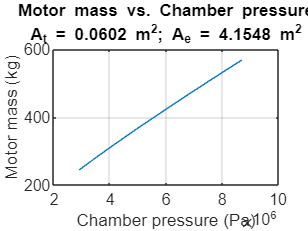

% Plotting results
plot(P_c, total_mass_P_c)
xlabel('Chamber pressure (Pa)')
ylabel('Motor mass (kg)')
title({'Motor mass vs. Chamber pressure' 'A_t = 0.0602 m^2; A_e = 4.1548 m^2'})
grid on

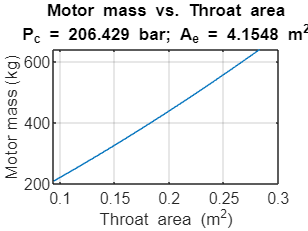


plot(A_t, total_mass_A_t)
xlabel('Throat area (m^2)')
ylabel('Motor mass (kg)')
title({'Motor mass vs. Throat area' 'P_c = 206.429 bar; A_e = 4.1548 m^2'})
grid on

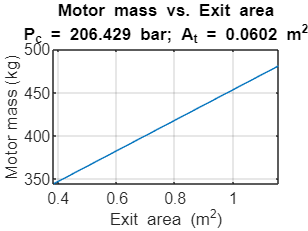


plot(A_e, total_mass_A_e)
xlabel('Exit area (m^2)')
ylabel('Motor mass (kg)')
title({'Motor mass vs. Exit area' 'P_c = 206.429 bar; A_t = 0.0602 m^2'})
grid on

## Calculating objective function in design space

% Initializing objective and constraint function values
total_mass_val = zeros(length(P_c), length(A_t), length(A_e));
ineq_constraint = zeros(length(P_c), length(A_t), length(A_e));
eq_constraint = zeros(length(P_c), length(A_t), length(A_e));

% Calculating objective and constraint functions
for i = 1:length(P_c)
    for j = 1:length(A_t)
        for k = 1:length(A_e)
            x_scaled = scale([P_c(i), A_t(j), A_e(k)], x_ref);
            total_mass_val(i, j, k) = calc_objective(x_scaled);
            [ineq_constraint(i,j,k), eq_constraint(i,j,k)] = calc_constraints(x_scaled);
        end
    end
end

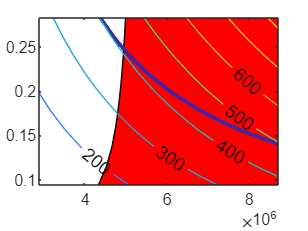

% Example plot
clf
i = 4;
contourf(P_c, A_t, ineq_constraint(:, :, i), [0,0], 'FaceColor', '#FF0000');
hold on
[M,c] = contour(P_c, A_t, eq_constraint(:, :, i), [0,0]);
c.LineWidth = 2;
contour(P_c, A_t, total_mass_val(:,:, i), 'ShowText','on')
hold off

%% Sample SQP conditions
% Linear constraints
A = []; 
b = [];
Aeq = [];
beq = [];

% Design variable bounds
lb = [0.1, 0.1, 0.1];
ub = [10, 10, 10];

options = optimoptions('fmincon','Display','iter','Algorithm','sqp');
x0 = [1, 1, 1];
[x, fval, exitflag, output, lambda] = fmincon(@calc_objective_test, x0, ...
    A, b, Aeq, beq, lb, ub, @calc_constraints, options)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           4    3.116809e+04     6.872e-02     1.000e+00     0.000e+00     2.655e+04  
    1           8    7.344800e+03     8.200e-01     1.000e+00     1.559e+00     5.856e+02  
    2          13    1.038875e+04     4.439e-02     7.000e-01     7.379e+00     2.732e+03  
    3          19    1.083440e+04     2.703e-02     4.900e-01     1.727e+00     2.170e+03  
    4          30    1.092015e+04     2.494e-02     8.235e-02     4.527e-01     1.979e+03  
    5          39    1.111914e+04     2.095e-02     1.681e-01     3.378e-01     1.904e+03  
    6          47    1.136313e+04     1.635e-02     2.401e-01     4.870e-01     1.659e+03  
    7          54    1.167397e+04     1.500e-02     3.430e-01     3.048e-01     1.504e+03  
    8          60    1.200155e+04     1.183e-02     4.900e-01     4.044e-01     1.

x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 1

output = struct with fields:
         iterations: 13
          funcCount: 80
          algorithm: 'sqp'
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 2.060585e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 1.345479e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
    constrviolation: 1.3455e-11
           stepsize: 1.1278e-04
       lssteplength: 1
      firstorderopt: 0.0062
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04
         lower: [3×1 double]
         upper: [3×1 double]


x = descale(x, x_ref);
fprintf('Chamber pressure = %f\nThroat area = %f\nExit area = %f\nTotal Mass = %f' ...
    , x(1), x(2), x(3), fval)

Chamber pressure = 1459198.304264
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637522

options = optimoptions('fmincon','Display','iter','Algorithm','active-set');
tic
for i=1:100
x0 = lb + rand(size(lb)).*(ub - lb);
[x, fval, exitflag, output, lambda] = fmincon(@calc_objective_test, x0, ...
    A, b, Aeq, beq, lb, ub, @calc_constraints, options)
x = descale(x, x_ref);
fprintf('Chamber pressure = %f\nThroat area = %f\nExit area = %f\nTotal Mass = %f' ...
    , x(1), x(2), x(3), fval)
if(i==1)
    fvalref=output.bestfeasible.fval;
    ssq=0
end
ssq=ssq+abs(output.bestfeasible.fval-fvalref);
end


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       192409         20.3                                         Infeasible start point
    1      8      7590.72       0.6909            1    -2.66e+04     1.14e+05   
    2     12      10729.8       0.4702            1          469     1.55e+04   
    3     17      10804.2       0.2697          0.5         14.5     2.16e+04   
    4     22      10076.1       0.5751          0.5         -155     2.89e+04  Hessian modified  
    5     26      9355.65       0.2354            1         -182     3.21e+04   
    6     30      11322.1       0.1299            1          625     1.63e+04   
    7     34      12084.6      0.00503            1          509     1.58e+04   
    8     38      12394.9     0.004173            1          473     2.41e+03   
    9     42      12428.2    1.058e-05            1          631

x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 12
          funcCount: 50
       lssteplength: 1
           stepsize: 5.3886e-07
          algorithm: 'active-set'
      firstorderopt: 7.3069e-05
    constrviolation: 6.2972e-13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 5.383756e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 6.297185e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.308294
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637523

ssq = 0


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       298698           31                                         Infeasible start point
    1      8      7602.92       0.7663            1    -2.33e+04     4.37e+05   
    2     12      9430.75       0.0837            1          183     2.39e+04   
    3     17      9665.68       0.1968          0.5         95.2     3.12e+04   
    4     21      10416.3       0.1393            1          112     1.37e+04   
    5     25      8627.18       0.2768            1         -366          960   
    6     29      10195.8       0.3432            1          451     8.29e+03   
    7     33      11698.9      0.02844            1     1.11e+03     1.42e+04   
    8     37      11720.7      0.01067            1         10.6     4.53e+03   
    9     41      12350.5      0.01548            1     1.02e+03     1.17e+03   


x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 13
          funcCount: 53
       lssteplength: 1
           stepsize: 1.6703e-06
          algorithm: 'active-set'
      firstorderopt: 2.1968e-04
    constrviolation: 1.0377e-10
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 1.668997e-06,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 1.037679e-10, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.333549
Throat area = 0.729036
Exit area = 6.010553
Total Mass = 12428.637516


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      55319.2        7.669                                         Infeasible start point
    1      8      8101.25       0.4706            1    -1.48e+04     3.53e+04   
    2     12      10870.3      0.02954            1          562      4.7e+03   
    3     18      10966.4       0.0258         0.25         41.6     7.24e+03   
    4     22      11867.6      0.05571            1          347          500   
    5     26      11927.4     0.008037            1         22.3     5.42e+03   
    6     30      12253.3     0.004175            1          225          599   
    7     34      12410.7     0.001122            1          309          695   
    8     38      12428.5    6.862e-06            1          615         3.24   
    9     42      12428.6    1.342e-09            1         79.9        0.525   


x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 11
          funcCount: 46
       lssteplength: 1
           stepsize: 4.6805e-07
          algorithm: 'active-set'
      firstorderopt: 6.1589e-05
    constrviolation: 3.0067e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 4.676815e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 3.006650e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.301073
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637521


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       290980        29.76                                         Infeasible start point
    1      8      7514.76       0.7363            1    -2.81e+04     3.06e+05   
    2     12      9068.36       0.5125            1          141     5.11e+04   
    3     16      8962.55       0.1712            1        -22.4     2.49e+03   
    4     21      9470.52       0.3135          0.5          153      6.2e+03   
    5     25      10369.2      0.03938            1          148     2.86e+04   
    6     29      11554.6       0.2077            1          448      1.4e+03   
    7     33        12126     0.005281            1          754     5.38e+03   
    8     37        12413     0.003308            1     1.17e+03          275   
    9     41      12427.2    1.941e-05            1          110          125   


x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 12
          funcCount: 49
       lssteplength: 1
           stepsize: 9.6947e-07
          algorithm: 'active-set'
      firstorderopt: 1.3059e-04
    constrviolation: 2.0109e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 9.686019e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 2.010947e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.302454
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       113734        10.49                                         Infeasible start point
    1      8      7522.24        0.729            1    -1.55e+04     3.38e+04   
    2     12      10376.9       0.1762            1          277     6.08e+04   
    3     16      10125.6       0.6733            1        -27.1     1.69e+04  Hessian modified  
    4     20      8039.21       0.4868            1         -451     7.71e+03   
    5     24        10519      0.05473            1          809     1.08e+04   
    6     28      11059.7      0.08562            1          194     1.85e+03   
    7     32      12228.3      0.02992            1     1.28e+03     1.25e+03   
    8     36      12419.1    0.0002256            1          629          178   
    9     40        12421    0.0001172            1         5.52

x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 13
          funcCount: 52
       lssteplength: 1
           stepsize: 1.6432e-06
          algorithm: 'active-set'
      firstorderopt: 1.5796e-04
    constrviolation: 1.7319e-14
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 1.641750e-06,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 1.731948e-14, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.307242
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       245128        24.68                                         Infeasible start point
    1      8      7506.83       0.7243            1    -2.63e+04     1.39e+05   
    2     12      11336.7       0.3514            1          310     8.87e+03   
    3     16      11285.9        0.434            1         7.02     6.76e+03   
    4     20       9418.6       0.2705            1         -576     3.21e+03   
    5     24      11497.2      0.07326            1      1.1e+03     9.02e+03   
    6     28      12343.5     0.008919            1     1.49e+03     1.31e+03   
    7     32      12428.1     3.46e-05            1     1.58e+03         6.46   
    8     36      12428.6    2.125e-08            1          106         7.39   
    9     40      12428.6    1.495e-08            1      -0.0992        0.111   


x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 11
          funcCount: 44
       lssteplength: 1
           stepsize: 1.0115e-06
          algorithm: 'active-set'
      firstorderopt: 1.4906e-04
    constrviolation: 8.5043e-14
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 1.010570e-06,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 8.504308e-14, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.309921
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      37502.4        4.711                                         Infeasible start point
    1      8      8114.19       0.4658            1     -1.6e+04     2.91e+03   
    2     12      10857.3      0.02955            1          566      5.9e+03   
    3     18      10949.3      0.02586         0.25         39.8     7.07e+03   
    4     22      11873.7      0.05571            1          354     2.54e+03   
    5     26      12054.2     0.005311            1         76.6     3.77e+03   
    6     30      12387.6     0.003108            1          569          584   
    7     34      12424.9    8.742e-05            1          166          146   
    8     38      12428.6    2.998e-07            1          611         2.05   
    9     42      12428.6    1.625e-10            1         10.8       0.0464   


x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 5

output = struct with fields:
         iterations: 11
          funcCount: 46
       lssteplength: 1
           stepsize: 2.3634e-06
          algorithm: 'active-set'
      firstorderopt: 4.0571e-04
    constrviolation: 1.2623e-13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵8.666049e-09, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 1.262324e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.273436
Throat area = 0.729036
Exit area = 6.010556
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       191336        18.07                                         Infeasible start point
    1      8      7447.39       0.8391            1    -1.78e+04     3.68e+03   
    2     12      9229.17       0.1421            1          145     1.56e+04   
    3     16      9223.17       0.4877            1         14.5     1.51e+04   
    4     20      8710.37        0.252            1        -86.3     3.22e+03   
    5     24      10145.1       0.2235            1          331     2.89e+03   
    6     28      11288.1      0.01863            1          415     1.34e+04   
    7     32      12087.6      0.02778            1          462          755   
    8     36      12370.8     0.002028            1          354          994   
    9     40      12426.9    0.0001114            1          379         89.6   


x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 12
          funcCount: 48
       lssteplength: 1
           stepsize: 1.8874e-06
          algorithm: 'active-set'
      firstorderopt: 2.4707e-04
    constrviolation: 5.7375e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 1.885632e-06,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 5.737510e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.287223
Throat area = 0.729036
Exit area = 6.010555
Total Mass = 12428.637519


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      44774.1        2.903                                         Infeasible start point
    1      8      7536.98       0.7129            1    -6.55e+03      1.3e+04   
    2     12      10029.3       0.1119            1          230     5.78e+04   
    3     16      9721.87       0.2053            1        -53.2     9.07e+03  Hessian modified  
    4     20      11664.5        0.116            1          789      1.1e+06   
    5     24      12308.2     0.002809            1          695     4.87e+03   
    6     28        12411     0.001182            1          129     3.29e+03   
    7     32      12427.6     7.31e-05            1         65.9     2.89e+03   
    8     36      12425.5    4.517e-05            1        -9.16     1.17e+03   
    9     40      12428.6    2.989e-07            1          230

x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 12
          funcCount: 48
       lssteplength: 1
           stepsize: 7.9091e-07
          algorithm: 'active-set'
      firstorderopt: 1.0311e-04
    constrviolation: 5.1452e-10
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 7.890728e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 5.145163e-10, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.268058
Throat area = 0.729036
Exit area = 6.010556
Total Mass = 12428.637488


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       201295        8.794                                         Infeasible start point
    1      8      7256.23       0.9146            1    -1.82e+04     2.45e+03   
    2     12      9228.52       0.1426            1          108     1.31e+04   
    3     16      9137.19       0.4398            1         -1.8     1.31e+04   
    4     20      8820.84       0.2126            1        -42.3     7.03e+03   
    5     24      9942.17       0.1757            1          244     1.72e+03   
    6     28      11333.8      0.08866            1          529     1.02e+04   
    7     32      12318.9      0.01108            1          871     2.48e+03   
    8     36      12381.2    0.0007445            1         75.3          471   
    9     40      12427.4    5.169e-05            1          409         36.6   


x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 12
          funcCount: 48
       lssteplength: 1
           stepsize: 5.3560e-07
          algorithm: 'active-set'
      firstorderopt: 7.1030e-05
    constrviolation: 3.3494e-10
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 5.355044e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 3.349443e-10, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.330981
Throat area = 0.729036
Exit area = 6.010553
Total Mass = 12428.637502


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       141295        6.462                                         Infeasible start point
    1      8      7284.51       0.9017            1    -1.79e+04     1.36e+03   
    2     12      9228.62       0.1425            1          115      1.2e+04   
    3     16      9190.68        0.351            1         4.05      1.1e+04   
    4     20       9657.9       0.1658            1         65.9     2.14e+04   
    5     24      9215.67        0.126            1         -120     8.85e+03   
    6     28      10163.8       0.3271            1          244      8.7e+03   
    7     32      11844.5      0.03138            1     2.19e+03     1.18e+04   
    8     36      12160.9     0.009323            1          182     2.19e+03   
    9     40      12359.3     0.002584            1          187          945   


x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 14
          funcCount: 56
       lssteplength: 1
           stepsize: 8.9922e-07
          algorithm: 'active-set'
      firstorderopt: 9.1839e-05
    constrviolation: 1.4766e-14
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 8.984121e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 1.476597e-14, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.307380
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       100684        16.13                                         Infeasible start point
    1      8      8086.96       0.5013            1    -1.63e+04     3.28e+04   
    2     12      9583.22       0.4859            1          187     2.08e+04   
    3     16      8776.69       0.2273            1         -173      7.5e+03   
    4     20      10079.2       0.7434            1          241     1.59e+04   
    5     24      8103.05       0.4791            1         -403      3.4e+03   
    6     28      10631.7      0.05468            1     1.89e+03     1.88e+04   
    7     32      10938.3      0.03411            1          107     1.83e+03   
    8     36      12078.3      0.06729            1          953     2.04e+03   
    9     40      12419.8     0.001064            1      1.8e+03          807   


x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 13
          funcCount: 52
       lssteplength: 1
           stepsize: 6.9903e-08
          algorithm: 'active-set'
      firstorderopt: 9.0202e-06
    constrviolation: 1.4578e-10
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 6.983333e-08,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 1.457774e-10, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.301264
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637522


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       139439        18.74                                         Infeasible start point
    1      8      7843.78       0.6354            1     -1.5e+04     7.84e+04   
    2     12      8923.63       0.4881            1           97     5.85e+03   
    3     16      8022.16       0.5251            1         -122          831   
    4     20      10070.4        0.115            1          458     1.58e+04   
    5     24         9086       0.1462            1         -186     2.53e+03   
    6     28      9895.67       0.5754            1          183      1.2e+04   
    7     32      8404.79        0.382            1         -320          927   
    8     36      10465.7       0.1149            1     1.48e+03     1.46e+04   
    9     40      11938.1      0.06745            1          965     6.15e+03   


x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 15
          funcCount: 60
       lssteplength: 1
           stepsize: 1.5378e-07
          algorithm: 'active-set'
      firstorderopt: 2.0014e-05
    constrviolation: 1.2157e-13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 1.536453e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 1.215694e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.290344
Throat area = 0.729036
Exit area = 6.010555
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       226509        18.43                                         Infeasible start point
    1      8      7430.02       0.7646            1    -2.66e+04     8.36e+04   
    2     12      10819.9        0.273            1          224     2.42e+04   
    3     16      10715.2       0.5322            1         8.56     4.35e+03   
    4     20      8175.59       0.4467            1         -517     1.76e+03   
    5     24        10823      0.03196            1          709      1.1e+04   
    6     28      12125.5       0.1101            1          789     2.39e+04   
    7     32      12409.9     0.002025            1          389          447   
    8     37      12331.6     0.001577          0.5        -82.6     5.61e+03   
    9     41      12404.4     0.000719            1          112          289   


x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 5

output = struct with fields:
         iterations: 14
          funcCount: 57
       lssteplength: 1
           stepsize: 5.5981e-06
          algorithm: 'active-set'
      firstorderopt: 2.0899e-04
    constrviolation: 1.3323e-15
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵1.110600e-09, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 1.332268e-15, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.318072
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       229822        14.46                                         Infeasible start point
    1      8      7336.36       0.8317            1    -2.53e+04     5.62e+04   
    2     12      11650.3       0.4641            1          346     1.11e+05   
    3     16      10743.8       0.6181            1         -134     1.51e+04  Hessian modified  
    4     20      7988.03       0.5035            1         -685     1.05e+04   
    5     24      10789.6       0.0509            1          897     8.94e+03   
    6     28      11234.1      0.04817            1          145     8.26e+03   
    7     32      12211.9      0.03749            1          884      2.2e+03   
    8     36      12380.2    0.0006697            1          268          616   
    9     40      12426.5    6.229e-05            1          300

x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 12
          funcCount: 48
       lssteplength: 1
           stepsize: 1.8080e-06
          algorithm: 'active-set'
      firstorderopt: 2.3700e-04
    constrviolation: 1.7210e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 1.806333e-06,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 1.720990e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.290932
Throat area = 0.729036
Exit area = 6.010555
Total Mass = 12428.637522


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       264891        16.44                                         Infeasible start point
    1      8      7325.29       0.8354            1    -2.65e+04     6.61e+04   
    2     12        11409       0.4236            1          314     1.16e+05   
    3     16      10618.2       0.5912            1         -116     1.47e+04  Hessian modified  
    4     20      8390.09       0.4503            1         -499     1.38e+04   
    5     24      10533.5      0.06333            1          777     1.21e+04   
    6     28      10963.5      0.06774            1          159          878   
    7     32      12102.2      0.03811            1          843     2.77e+03   
    8     36      12420.4    0.0005116            1     3.19e+03          122   
    9     40        12425    6.033e-05            1         18.6

x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 13
          funcCount: 52
       lssteplength: 1
           stepsize: 5.8254e-07
          algorithm: 'active-set'
      firstorderopt: 7.8048e-05
    constrviolation: 8.6775e-13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 5.820172e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 8.677503e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.321137
Throat area = 0.729036
Exit area = 6.010553
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4        73208        2.622                                         Infeasible start point
    1      8      7295.37       0.8969            1    -8.76e+03     1.13e+03   
    2     12      8466.72       0.3331            1         97.3     3.98e+03   
    3     16      10360.4       0.1571            1          514     6.69e+03   
    4     21      10644.4      0.09855          0.5         77.1     1.15e+04   
    5     25        10651      0.04204            1         3.41     4.07e+03   
    6     29      11801.9       0.1193            1          473     4.14e+03   
    7     33      12210.7     0.003882            1          351     3.93e+03   
    8     37      12344.3      0.00133            1          138          202   
    9     41      12427.3    0.0002134            1          789          107   


x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 13
          funcCount: 53
       lssteplength: 1
           stepsize: 9.2082e-07
          algorithm: 'active-set'
      firstorderopt: 9.1840e-05
    constrviolation: 5.8842e-15
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 9.200006e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 5.884182e-15, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.306934
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       266390        4.328                                         Infeasible start point
    1      8      7186.56       0.9507            1    -2.52e+04     1.45e+03   
    2     12      9245.74       0.1321            1         78.4     4.76e+04   
    3     16      9439.14       0.1435            1         51.3     7.27e+03   
    4     20      10919.8       0.2855            1          439     4.42e+04   
    5     24      11670.1      0.01283            1          588     7.99e+03   
    6     28      12157.7      0.02553            1          197     1.05e+03   
    7     32      12353.4     0.001018            1          179     2.35e+03   
    8     36      12426.2    0.0002158            1          401          511   
    9     40      12428.6    1.248e-07            1          193         14.8   


x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 12
          funcCount: 48
       lssteplength: 1
           stepsize: 6.3599e-07
          algorithm: 'active-set'
      firstorderopt: 8.4467e-05
    constrviolation: 4.7603e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 6.354105e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 4.760303e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.284439
Throat area = 0.729036
Exit area = 6.010555
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       155749        17.86                                         Infeasible start point
    1      8      7652.91       0.6508            1    -2.27e+04     8.07e+04   
    2     12      10956.3       0.2464            1          315     9.14e+03   
    3     16      11181.8       0.4304            1         60.2     7.06e+03   
    4     20       9456.4       0.2573            1         -527     2.83e+03   
    5     24      11485.6      0.08222            1     1.07e+03     8.64e+03   
    6     28      12350.2     0.007804            1     2.05e+03          343   
    7     32      12427.9    3.106e-05            1          745         38.6   
    8     36      12428.6    6.867e-07            1         23.6         2.66   
    9     40      12428.6    1.168e-08            1         13.5       0.0191   


x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 11
          funcCount: 44
       lssteplength: 1
           stepsize: 1.9588e-06
          algorithm: 'active-set'
      firstorderopt: 3.1248e-04
    constrviolation: 1.7231e-13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 1.957067e-06,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 1.723066e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.270069
Throat area = 0.729036
Exit area = 6.010556
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       275339        30.35                                         Infeasible start point
    1      8      7524.14       0.7166            1    -2.57e+04     2.95e+05   
    2     12        11519       0.3725            1          345     4.06e+03   
    3     16      11491.3       0.4114            1          7.3     7.39e+03   
    4     20      10697.5       0.1285            1         -315        1e+04   
    5     24      10994.7      0.02367            1         68.4     5.21e+03   
    6     28      12062.5      0.07602            1          665     4.83e+03   
    7     32      12393.1     0.001108            1     1.49e+03     1.12e+03   
    8     36      12428.3    5.844e-05            1          518         1.45   
    9     40      12428.6    5.782e-08            1         41.2        0.913   


x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 11
          funcCount: 44
       lssteplength: 1
           stepsize: 1.1868e-06
          algorithm: 'active-set'
      firstorderopt: 1.6512e-04
    constrviolation: 5.6122e-13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 1.185696e-06,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 5.612177e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.302744
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      42031.5        7.838                                         Infeasible start point
    1      8      8886.33       0.2156            1    -1.56e+04     1.48e+04   
    2     13      9416.87       0.2481          0.5          136     1.02e+04   
    3     17      10217.9      0.04402            1          138     4.44e+03   
    4     21      11370.5         0.25            1          372     6.84e+03   
    5     25      11065.3      0.05718            1        -77.2     1.35e+04   
    6     30        10637      0.05487          0.5         -173     3.61e+03   
    7     34      11942.4      0.09402            1          891     4.56e+03   
    8     38        12428     0.002265            1     1.15e+03     1.66e+03   
    9     42        12422    9.488e-05            1        -20.1          684   


x =     0.2516    3.8655    7.8080


fval = 1.2429e+04

exitflag = 5

output = struct with fields:
         iterations: 13
          funcCount: 54
       lssteplength: 1
           stepsize: 2.7609e-05
          algorithm: 'active-set'
      firstorderopt: 0.0037
    constrviolation: 4.6285e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵2.104041e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 4.628520e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9304e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459197.863066
Throat area = 0.729036
Exit area = 6.010575
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       219538        20.26                                         Infeasible start point
    1      8      7439.34       0.8102            1    -2.17e+04      2.8e+05   
    2     12      13048.4       0.6183            1          571     8.98e+04   
    3     16      8388.86       0.3833            1         -723     2.71e+03  Hessian modified twice  
    4     20      10355.4       0.1217            1          829     1.32e+04   
    5     24      10852.7      0.02848            1          101     1.41e+03   
    6     28      11867.7       0.0971            1          390     6.85e+03   
    7     33      11880.2      0.07184          0.5          5.8     8.76e+03   
    8     38      11050.8      0.07347          0.5         -395     5.21e+03   
    9     42      12242.4      0.03865            1     1.

x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 15
          funcCount: 62
       lssteplength: 1
           stepsize: 6.6767e-07
          algorithm: 'active-set'
      firstorderopt: 9.2146e-05
    constrviolation: 1.9573e-13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 6.670692e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 1.957323e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.292478
Throat area = 0.729036
Exit area = 6.010555
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       113974        5.397                                         Infeasible start point
    1      8      7298.49       0.8956            1    -1.19e+04     1.78e+03   
    2     12      8900.43       0.1878            1          113      6.1e+03   
    3     16      9702.73       0.1206            1          188     4.65e+03   
    4     20      10863.3       0.2959            1          202     1.69e+04   
    5     25      9712.67       0.2471          0.5         -407     8.66e+03   
    6     29        11823      0.08244            1      1.5e+03     8.34e+03   
    7     33        12239     0.002657            1          238      1.7e+03   
    8     37      12421.1     0.000966            1          963         90.8   
    9     41      12428.5    2.126e-06            1          137         16.5   


x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 5

output = struct with fields:
         iterations: 12
          funcCount: 49
       lssteplength: 1
           stepsize: 2.3515e-06
          algorithm: 'active-set'
      firstorderopt: 2.1459e-04
    constrviolation: 1.2068e-13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵4.296716e-10, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 1.206812e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.326476
Throat area = 0.729036
Exit area = 6.010553
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       132348        11.33                                         Infeasible start point
    1      8      7505.01       0.7387            1    -2.55e+04     2.46e+04   
    2     12      9151.07       0.5058            1          150     4.45e+04   
    3     16      8913.87       0.1847            1        -49.7     5.22e+03   
    4     21      9480.91       0.3136          0.5          173     6.89e+03   
    5     25      11046.2      0.02434            1          391     1.92e+04   
    6     29      12071.3       0.0925            1          611     2.91e+03   
    7     33      12433.8     0.002016            1          768     1.35e+03   
    8     37        12420     0.000131            1          -41          911   
    9     41      12428.6    1.815e-06            1          375         38.6   


x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 5

output = struct with fields:
         iterations: 12
          funcCount: 49
       lssteplength: 1
           stepsize: 2.8730e-06
          algorithm: 'active-set'
      firstorderopt: 3.8266e-04
    constrviolation: 1.1820e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵7.836863e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 1.182032e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.275263
Throat area = 0.729036
Exit area = 6.010556
Total Mass = 12428.637522


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      48779.6        5.926                                         Infeasible start point
    1      8      7934.94       0.5377            1    -1.53e+04     3.07e+03   
    2     12      11122.7        0.118            1          550     7.09e+03   
    3     17      11327.6      0.02994          0.5         47.9        1e+04   
    4     22      10952.2      0.02481          0.5         -160     3.94e+03   
    5     26      12045.4      0.06708            1          846     2.12e+03   
    6     30      12408.2     0.000807            1     3.33e+03     1.52e+03   
    7     34      12426.2    3.492e-05            1          103         42.8   
    8     38      12428.6    4.071e-07            1          186         1.12   
    9     42      12428.6    3.869e-11            1         63.7      0.00171   


x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 10
          funcCount: 42
       lssteplength: 1
           stepsize: 1.1086e-06
          algorithm: 'active-set'
      firstorderopt: 1.4572e-04
    constrviolation: 3.8688e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 1.107625e-06,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 3.868839e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.325167
Throat area = 0.729036
Exit area = 6.010553
Total Mass = 12428.637521


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       213898        3.594                                         Infeasible start point
    1      8      7189.07       0.9499            1    -1.79e+04     1.77e+03   
    2     12      9236.23       0.1377            1         80.3     1.19e+04   
    3     16      9260.29       0.2502            1         9.67     7.93e+03   
    4     20      10068.7       0.1825            1          113     2.36e+04   
    5     24      8692.88       0.2546            1         -360      7.2e+03   
    6     28        10023       0.4195            1          328     1.23e+03   
    7     32      12192.6      0.06474            1      1.6e+03     1.16e+04   
    8     36      12443.9      0.01038            1          312     3.73e+03   
    9     40      12152.5     0.008449            1         -153     6.99e+03   


x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 15
          funcCount: 60
       lssteplength: 1
           stepsize: 5.2444e-07
          algorithm: 'active-set'
      firstorderopt: 6.5604e-05
    constrviolation: 3.0287e-13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 5.239677e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 3.028688e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.298167
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       106877        11.03                                         Infeasible start point
    1      8      7643.11       0.6619            1    -2.54e+04     4.09e+04   
    2     12      11530.3       0.3135            1          427     6.17e+03   
    3     16      11648.2       0.2054            1         46.8        3e+03   
    4     20      10441.7       0.1068            1         -244     6.35e+03   
    5     24      11000.9      0.02549            1          119     7.87e+03   
    6     28      12038.1      0.08239            1          521     5.43e+03   
    7     33      11697.8      0.06027          0.5          -92     8.59e+03   
    8     37      11149.8      0.04241            1         -149     1.08e+03   
    9     41      12180.9      0.04539            1          948     1.28e+03   


x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 14
          funcCount: 57
       lssteplength: 1
           stepsize: 6.8698e-07
          algorithm: 'active-set'
      firstorderopt: 8.4635e-05
    constrviolation: 1.6220e-10
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 6.864574e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 1.621950e-10, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.295348
Throat area = 0.729036
Exit area = 6.010555
Total Mass = 12428.637519


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       106844        3.878                                         Infeasible start point
    1      8      7266.18       0.9099            1    -1.16e+04      1.5e+03   
    2     12      8840.18       0.2057            1          104     5.19e+03   
    3     16      9763.14       0.1119            1          209     4.08e+03   
    4     21      10323.7       0.1241          0.5          162     9.97e+03   
    5     25      11110.4       0.0234            1          172     1.32e+03   
    6     29      11996.7       0.0637            1          363     3.66e+03   
    7     33      12408.1    0.0003354            1      7.6e+03         54.7   
    8     37      12426.5    3.168e-05            1          107         98.9   
    9     41      12428.6    1.349e-06            1           65         7.18   


x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 11
          funcCount: 45
       lssteplength: 1
           stepsize: 7.6353e-07
          algorithm: 'active-set'
      firstorderopt: 9.2623e-05
    constrviolation: 1.2951e-10
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 7.628490e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 1.295103e-10, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.275762
Throat area = 0.729036
Exit area = 6.010556
Total Mass = 12428.637522


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       184506        3.714                                         Infeasible start point
    1      8      7199.56       0.9431            1    -1.63e+04     1.76e+03   
    2     12      9236.28       0.1377            1         85.9     9.72e+03   
    3     16      9260.78       0.2335            1         9.01     7.18e+03   
    4     20      10111.6       0.2022            1          121     2.29e+04   
    5     24      8648.25       0.2688            1         -369     5.82e+03   
    6     28      10086.4       0.4275            1          357     2.14e+03   
    7     32      12240.3      0.06724            1      1.5e+03     1.15e+04   
    8     36      12419.7     0.008509            1          207     4.49e+03   
    9     40      12206.8     0.005796            1         -128     5.88e+03   


x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 14
          funcCount: 56
       lssteplength: 1
           stepsize: 5.2095e-07
          algorithm: 'active-set'
      firstorderopt: 6.8388e-05
    constrviolation: 2.2451e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 5.204693e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 2.245104e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.298371
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637522


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       210718         7.26                                         Infeasible start point
    1      8       7232.7       0.9262            1    -2.16e+04     1.67e+03   
    2     12      9228.43       0.1427            1          100     1.93e+04   
    3     16      9170.44       0.4317            1         3.48     1.34e+04   
    4     20       8750.6        0.235            1        -53.9     1.12e+04   
    5     24      9654.28      0.06409            1          182     4.69e+03   
    6     28      10621.1       0.4421            1          246     2.54e+04   
    7     32      9867.95       0.1721            1         -242     4.93e+03   
    8     36      11261.7       0.1061            1          476     1.35e+04   
    9     40      12198.3     0.005346            1          461          589   


x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 15
          funcCount: 60
       lssteplength: 1
           stepsize: 9.6067e-09
          algorithm: 'active-set'
      firstorderopt: 1.2670e-06
    constrviolation: 6.9722e-14
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 9.598233e-09,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 6.972201e-14, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.315849
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       238261        22.54                                         Infeasible start point
    1      8      7530.47       0.7913            1     -2.1e+04      1.9e+05   
    2     12      9430.45       0.0837            1          169     1.55e+04   
    3     17      9665.61       0.1967          0.5         95.3     1.64e+04   
    4     22      9978.96       0.1226          0.5         75.4      9.2e+03   
    5     26      10809.7      0.03033            1          179     2.75e+03   
    6     30      11831.6      0.09752            1          378     7.06e+03   
    7     34      12363.1     0.001621            1          917     2.49e+03   
    8     38      12372.1     0.000782            1         11.2          877   
    9     42      12428.2    8.388e-05            1     1.63e+03          123   


x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 13
          funcCount: 54
       lssteplength: 1
           stepsize: 1.1613e-06
          algorithm: 'active-set'
      firstorderopt: 2.0957e-04
    constrviolation: 2.9865e-14
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 1.160256e-06,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 2.986500e-14, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.326314
Throat area = 0.729036
Exit area = 6.010553
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       276175        28.27                                         Infeasible start point
    1      8      61723.9        1.796            1    -1.42e+04     2.41e+05   
    2     12      7457.95       0.8918            1    -2.76e+04          304   
    3     16      8977.31       0.1659            1          132     2.71e+03   
    4     20      9677.26       0.2254            1          181      5.4e+03   
    5     24      11598.7      0.09294            1     1.38e+03     6.79e+03   
    6     28      12364.4     0.002782            1     8.35e+03     2.43e+03   
    7     32      12435.9    0.0001057            1     2.02e+03         44.4   
    8     36      12434.2    2.243e-06            1        -32.4          759   
    9     46        12434    2.228e-06       0.0156        -37.6          853   


x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 26
          funcCount: 164
       lssteplength: 1
           stepsize: 7.0966e-07
          algorithm: 'active-set'
      firstorderopt: 8.8050e-05
    constrviolation: 1.3067e-13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 7.090290e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 1.306732e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.315922
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       120150        11.22                                         Infeasible start point
    1      8      7532.38         0.79            1    -1.22e+04     3.89e+04   
    2     12      8825.83       0.5064            1          105     7.89e+03   
    3     16      8190.11       0.4471            1        -94.4        3e+03   
    4     20      10544.8      0.05761            1     1.33e+03      1.3e+04   
    5     24        10225      0.05873            1        -64.2     5.89e+03   
    6     28      11551.4       0.1892            1          559     6.36e+03   
    7     32      11703.8      0.01638            1         62.4     1.06e+04   
    8     36      11767.2     0.009798            1         25.6     1.49e+03   
    9     40      12358.7      0.01359            1          962     1.53e+03   


x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 14
          funcCount: 56
       lssteplength: 1
           stepsize: 2.7042e-08
          algorithm: 'active-set'
      firstorderopt: 3.5793e-06
    constrviolation: 3.6193e-14
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 2.701774e-08,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 3.619327e-14, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.315069
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      23529.6        2.164                                         Infeasible start point
    1      8      8157.61       0.4486            1    -6.25e+03          843   
    2     12      10771.3      0.04891            1     1.16e+03     6.37e+03  Hessian modified  
    3     16      11943.5      0.05909            1          452     6.89e+03   
    4     20      12085.1     0.004754            1         64.6     6.47e+03   
    5     24      12407.2     0.003024            1     1.01e+03     1.58e+03   
    6     28      12424.7    6.856e-05            1         71.8          795   
    7     32      12427.9    9.956e-06            1         30.7         24.5   
    8     36      12428.6    3.892e-08            1          178          2.5   
    9     40      12428.6    1.722e-12            1         27.3

x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 10
          funcCount: 40
       lssteplength: 1
           stepsize: 9.0552e-08
          algorithm: 'active-set'
      firstorderopt: 1.1736e-05
    constrviolation: 1.7224e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 9.047381e-08,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 1.722400e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.319991
Throat area = 0.729036
Exit area = 6.010553
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       192014        16.42                                         Infeasible start point
    1      8      7493.41       0.7899            1    -2.11e+04     9.55e+04   
    2     12      9138.24        0.125            1          161     1.02e+04   
    3     16      9419.02      0.08225            1         52.7     5.81e+03   
    4     20      10026.2       0.5846            1          132     8.97e+03   
    5     24      8381.17        0.403            1         -321     2.87e+03   
    6     28      10251.1      0.04931            1          786      1.6e+04   
    7     32      10909.7      0.05307            1          163     2.23e+03   
    8     36      11994.1      0.07049            1          545     1.83e+03   
    9     40      12292.6     0.002243            1          274     1.62e+03   


x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 14
          funcCount: 56
       lssteplength: 1
           stepsize: 4.4746e-08
          algorithm: 'active-set'
      firstorderopt: 1.0206e-05
    constrviolation: 1.5678e-10
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 4.400914e-08,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 1.567794e-10, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.318695
Throat area = 0.729036
Exit area = 6.010553
Total Mass = 12428.637513


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      25011.6        3.222                                         Infeasible start point
    1      8      8521.12       0.3234            1    -4.76e+03     2.35e+03   
    2     12        10446       0.2124            1          506     7.24e+03  Hessian modified  
    3     16      10273.9      0.09898            1        -20.4     1.89e+04   
    4     20      8760.77       0.2427            1         -268     5.28e+03   
    5     24      10135.8       0.4232            1          362     3.15e+03   
    6     28      11351.6      0.02859            1          605     1.41e+04   
    7     32      12027.3      0.03388            1          407     3.96e+03   
    8     36      12396.2     0.002141            1          809          250   
    9     40      12422.6    0.0001177            1         87.5

x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 12
          funcCount: 48
       lssteplength: 1
           stepsize: 1.0952e-06
          algorithm: 'active-set'
      firstorderopt: 1.8735e-04
    constrviolation: 4.3707e-09
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 1.093438e-06,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 4.370651e-09, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.269687
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637327


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      53954.8       0.3566                                         Infeasible start point
    1     10      42242.5       0.3193         0.25    -9.71e+03     3.48e+04   
    2     16      33490.9       0.2931         0.25    -9.57e+03      2.6e+04  Hessian modified  
    3     22      26978.2       0.2726         0.25    -1.23e+04     1.86e+04   
    4     28      22172.9       0.2524         0.25    -1.09e+04     1.44e+04   
    5     34      18596.9        0.235         0.25    -6.66e+03     1.04e+04   
    6     40      15958.3        0.219         0.25    -3.41e+03     7.53e+03   
    7     46      14036.6       0.2039         0.25    -1.67e+03     5.15e+03   
    8     51      12021.9       0.1906          0.5         -682      1.9e+04   
    9     55      12122.9     0.009033            1         86.6

x =     0.2516    3.8655    7.8080


fval = 1.2429e+04

exitflag = 5

output = struct with fields:
         iterations: 16
          funcCount: 79
       lssteplength: 1
           stepsize: 7.2213e-06
          algorithm: 'active-set'
      firstorderopt: 9.1663e-04
    constrviolation: 3.1127e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵2.026172e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 3.112732e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.172591
Throat area = 0.729036
Exit area = 6.010561
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       198541        19.44                                         Infeasible start point
    1      8      7591.23       0.7549            1    -1.99e+04     1.56e+05   
    2     12      9218.17       0.1032            1          175     1.27e+04   
    3     16      9665.56       0.2474            1          101     7.53e+03   
    4     20      10894.8      0.03055            1          346     1.26e+04   
    5     24      11431.4       0.0222            1          141     2.32e+03   
    6     28      12073.1      0.03011            1          261     5.89e+03   
    7     32      12406.3    0.0009499            1          413          300   
    8     36      12408.4    0.0003084            1         3.97          597   
    9     40      12428.2    1.073e-05            1          281         28.8   


x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 12
          funcCount: 48
       lssteplength: 1
           stepsize: 7.4732e-07
          algorithm: 'active-set'
      firstorderopt: 9.8205e-05
    constrviolation: 5.7686e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 7.465471e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 5.768597e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.315840
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637519


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      34314.2        0.157                                         Infeasible start point
    1      9      20712.8       0.1303          0.5    -4.21e+03     1.31e+04   
    2     16      19127.6       0.1249        0.125    -5.73e+03     1.06e+04   
    3     23      17753.3       0.1198        0.125    -3.98e+03     9.57e+03   
    4     30      16564.9        0.115        0.125    -2.76e+03     8.13e+03   
    5     37      15542.1       0.1104        0.125    -1.87e+03     6.81e+03   
    6     44      14682.9       0.1059        0.125     -1.2e+03     4.84e+03   
    7     50      13633.9      0.09868         0.25         -839     3.39e+03   
    8     54      12176.7      0.06053            1    -1.16e+03     6.64e+03   
    9     58      12417.5    0.0005661            1          193     1.49e+03   


x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 14
          funcCount: 74
       lssteplength: 1
           stepsize: 9.7703e-07
          algorithm: 'active-set'
      firstorderopt: 1.2931e-04
    constrviolation: 2.2283e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 9.761931e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 2.228262e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.320664
Throat area = 0.729036
Exit area = 6.010553
Total Mass = 12428.637522


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       284921        27.86                                         Infeasible start point
    1      8       7441.3        0.757            1    -2.58e+04     1.41e+05   
    2     12      9897.55      0.08548            1          174     7.88e+04   
    3     16      9883.19       0.3775            1         20.8     5.23e+04  Hessian modified  
    4     20      10676.1      0.03177            1          329     1.12e+04   
    5     24      11849.7       0.1377            1          559      5.7e+04   
    6     28      12417.4     0.003945            1     1.45e+03     9.85e+03   
    7     32      12371.4    0.0009439            1        -38.3          211   
    8     36      12416.4    0.0003225            1         97.1          615   
    9     40      12427.5    1.542e-05            1         85.7

x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 5

output = struct with fields:
         iterations: 12
          funcCount: 48
       lssteplength: 1
           stepsize: 3.0528e-06
          algorithm: 'active-set'
      firstorderopt: 3.6125e-04
    constrviolation: 1.7997e-13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵9.192277e-09, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 1.799672e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.326974
Throat area = 0.729036
Exit area = 6.010553
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       132466        7.503                                         Infeasible start point
    1      8      7364.22        0.813            1    -2.63e+04     1.35e+04   
    2     12      9251.47       0.4981            1          148     7.29e+04   
    3     16      8861.74       0.1997            1        -79.5     1.71e+04   
    4     21      9499.03       0.3267          0.5          192      7.4e+03   
    5     25      11946.5      0.03788            1     1.63e+03     1.77e+04   
    6     29      11818.9      0.01245            1        -49.1     1.12e+04   
    7     33      12375.4      0.01031            1     1.28e+03          872   
    8     37      12428.6    2.515e-05            1          884         49.3   
    9     41      12428.6    3.808e-07            1        0.458         42.2   


x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 12
          funcCount: 49
       lssteplength: 1
           stepsize: 1.8506e-06
          algorithm: 'active-set'
      firstorderopt: 2.0174e-04
    constrviolation: 4.8850e-13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 1.848991e-06,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 4.884981e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.324578
Throat area = 0.729036
Exit area = 6.010553
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       292267        27.25                                         Infeasible start point
    1      8      7392.46       0.8336            1    -2.45e+04     4.61e+05   
    2     12        13920       0.7626            1          640     1.05e+05   
    3     16      8373.95       0.3822            1         -884     2.61e+03  Hessian modified twice  
    4     20      10422.7       0.1572            1          926     1.26e+04   
    5     24      11087.3      0.02392            1          133     1.59e+03   
    6     28      11998.3       0.0696            1          381     5.39e+03   
    7     32      12335.4     0.002897            1          273     3.06e+03   
    8     36      12305.5     0.001922            1        -24.4          885   
    9     40      12426.2    0.0003732            1     1.

x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 12
          funcCount: 48
       lssteplength: 1
           stepsize: 1.0965e-06
          algorithm: 'active-set'
      firstorderopt: 1.4177e-04
    constrviolation: 7.5372e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 1.095564e-06,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 7.537193e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.314677
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      34643.9        5.902                                         Infeasible start point
    1      8      8825.62       0.2358            1    -1.31e+04     1.01e+04   
    2     13      9402.68       0.2431          0.5          149     1.06e+04   
    3     17        10090      0.04787            1          114     3.54e+03   
    4     21      11238.6       0.2839            1          352     6.97e+03   
    5     25      10314.9         0.13            1         -186     1.32e+04   
    6     30      9622.45       0.1364          0.5         -204     1.62e+03   
    7     34      11203.7       0.2507            1          594     5.75e+03   
    8     38      12314.8      0.01778            1     1.34e+03     5.95e+03   
    9     42      12392.9    0.0009535            1          141          629   


x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 14
          funcCount: 58
       lssteplength: 1
           stepsize: 9.4258e-08
          algorithm: 'active-set'
      firstorderopt: 1.2434e-05
    constrviolation: 9.4114e-13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 9.417489e-08,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 9.411361e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.299493
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       171521        2.588                                         Infeasible start point
    1      8      7192.14       0.9478            1    -2.07e+04          908   
    2     12      9236.25       0.1377            1           82     1.59e+04   
    3     16      9310.21       0.2121            1         19.5     7.46e+03   
    4     20      10667.9       0.1806            1          328     1.37e+04   
    5     24      11515.5      0.01404            1          230     7.45e+03   
    6     28      12281.1      0.03114            1          764      1.2e+03   
    7     32      12418.1    0.0001674            1          631          987   
    8     36      12426.8     2.44e-05            1         53.8         18.7   
    9     40      12428.6     1.15e-07            1          583         1.83   


x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 11
          funcCount: 44
       lssteplength: 1
           stepsize: 1.2810e-06
          algorithm: 'active-set'
      firstorderopt: 1.6912e-04
    constrviolation: 5.9039e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 1.279865e-06,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 5.903944e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.268229
Throat area = 0.729036
Exit area = 6.010556
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      49699.3        1.388                                         Infeasible start point
    1      8         7316       0.8882            1    -4.99e+03     1.16e+03   
    2     12      7787.03       0.6474            1         50.5     1.68e+03   
    3     16       9309.4       0.1015            1          196     3.25e+03   
    4     20      9635.25       0.3014            1         79.4          925   
    5     24      10518.5       0.0446            1          209     1.52e+04   
    6     28      10857.4      0.03392            1         80.7     2.92e+03   
    7     32      11909.3      0.08994            1          444     6.24e+03   
    8     36      12256.5     0.004242            1          240     3.53e+03   
    9     40      12270.8     0.002222            1         11.4          850   


x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 14
          funcCount: 56
       lssteplength: 1
           stepsize: 6.7332e-07
          algorithm: 'active-set'
      firstorderopt: 8.8944e-05
    constrviolation: 9.4195e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 6.728611e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 9.419487e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.301967
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637517


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       231335        28.11                                         Infeasible start point
    1      8      7597.17       0.6753            1    -2.27e+04     1.71e+05   
    2     12      9953.13      0.07182            1          174     3.08e+04   
    3     17      10070.1       0.1226          0.5         59.7     4.71e+03   
    4     21      11708.3       0.1747            1          807     1.23e+04   
    5     25      11975.6      0.00686            1          183     6.06e+03   
    6     29        12361     0.007684            1          390     1.53e+03   
    7     33      12428.1    1.145e-05            1          596          167   
    8     37      12428.5    1.771e-06            1          9.5         6.07   
    9     41      12428.6     2.71e-09            1           83       0.0482   


x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 5

output = struct with fields:
         iterations: 11
          funcCount: 45
       lssteplength: 1
           stepsize: 2.1282e-06
          algorithm: 'active-set'
      firstorderopt: 3.8200e-04
    constrviolation: 7.7049e-14
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵4.841892e-09, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 7.704948e-14, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.280679
Throat area = 0.729036
Exit area = 6.010555
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       292524        22.19                                         Infeasible start point
    1      8      7345.33       0.8764            1    -2.55e+04     3.46e+03   
    2     12      9228.83       0.1424            1          129     3.75e+04   
    3     16      9251.86       0.4912            1           20     1.57e+04   
    4     20      8626.39       0.2741            1        -98.3     4.91e+03   
    5     24      9959.48      0.08298            1          288     6.33e+03   
    6     28      11404.4       0.2546            1          525     3.51e+04   
    7     32      11827.6      0.01016            1          343     7.33e+03   
    8     36        12251      0.01385            1          232     1.34e+03   
    9     40      12419.7    0.0002794            1          433          863   


x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 13
          funcCount: 52
       lssteplength: 1
           stepsize: 1.6837e-06
          algorithm: 'active-set'
      firstorderopt: 2.2232e-04
    constrviolation: 7.3280e-10
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 1.682971e-06,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 7.328000e-10, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.310967
Throat area = 0.729036
Exit area = 6.010553
Total Mass = 12428.637485


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      77609.4        6.537                                         Infeasible start point
    1      8      7547.78       0.7124            1    -2.09e+04     4.25e+03   
    2     12      10534.2       0.4894            1          396     1.64e+04   
    3     17      10453.9       0.2821          0.5        -23.3      2.4e+04   
    4     22      9732.47       0.5633          0.5         -155      2.9e+04  Hessian modified  
    5     26      9446.56       0.1868            1          -83     2.48e+04   
    6     31      10661.9       0.2725          0.5          358     2.92e+05   
    7     35      11939.7      0.01765            1          541      2.1e+04   
    8     39      12481.8      0.01468            1          603     7.89e+03   
    9     43      12588.8    0.0001483            1          313

x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 24
          funcCount: 133
       lssteplength: 1
           stepsize: 7.7260e-08
          algorithm: 'active-set'
      firstorderopt: 1.0192e-05
    constrviolation: 1.1985e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 7.720997e-08,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 1.198486e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.294551
Throat area = 0.729036
Exit area = 6.010555
Total Mass = 12428.637522


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4        12773       0.3309                                         Infeasible start point
    1      8      7859.71       0.6653            1         -566     3.33e+03   
    2     12      9416.98      0.08486            1          206     2.63e+03   
    3     17       9644.7       0.1849          0.5         92.2     2.54e+03   
    4     21      10625.1       0.1378            1          165     1.85e+04   
    5     26      9686.13       0.1497          0.5         -363     5.99e+03   
    6     30      11329.4       0.1872            1          695     8.04e+03   
    7     34      12434.2      0.00931            1     1.05e+03     2.83e+03   
    8     39      12240.5     0.002898          0.5         -123          504   
    9     43        12402     0.001675            1          239          398   


x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 13
          funcCount: 55
       lssteplength: 1
           stepsize: 1.6260e-06
          algorithm: 'active-set'
      firstorderopt: 2.1411e-04
    constrviolation: 2.4116e-10
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 1.624133e-06,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 2.411554e-10, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.284944
Throat area = 0.729036
Exit area = 6.010555
Total Mass = 12428.637507


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       206015        24.33                                         Infeasible start point
    1      8      7707.49       0.6867            1    -2.25e+04      1.8e+05   
    2     12      8966.83       0.3767            1          120     8.91e+03   
    3     16      8357.73       0.3823            1         -100     2.95e+03   
    4     20      10468.7       0.1957            1          903     1.24e+04   
    5     24      10989.8      0.02569            1         95.1     3.67e+03   
    6     28      11970.1      0.07914            1          419     2.04e+03   
    7     32      12327.6     0.002009            1          395     2.36e+03   
    8     36      12377.8    0.0006734            1         64.1           80   
    9     40      12428.3    6.822e-05            1     1.62e+03           61   


x = 1×3
    0.2516    3.8655    7.8080


fval = 1.2429e+04

exitflag = 5

output = struct with fields:
         iterations: 12
          funcCount: 48
       lssteplength: 1
           stepsize: 6.6008e-06
          algorithm: 'active-set'
      firstorderopt: 8.6163e-04
    constrviolation: 5.3427e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵3.469956e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 5.342726e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.182553
Throat area = 0.729036
Exit area = 6.010560
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       258003        11.37                                         Infeasible start point
    1      8      7251.68       0.9167            1    -2.35e+04     2.25e+03   
    2     12       9228.5       0.1426            1          106     2.73e+04   
    3     16      9204.66       0.4544            1         10.3     1.44e+04   
    4     20      8716.17       0.2448            1        -70.7     6.87e+03   
    5     24      9858.92      0.07876            1          226      4.9e+03   
    6     28      11203.8       0.3177            1          430     2.69e+04   
    7     32      11480.4      0.01857            1          176     6.75e+03   
    8     36      12113.8      0.02826            1          277     4.91e+03   
    9     40      12410.7    0.0006225            1          482          954   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 14
          funcCount: 56
       lssteplength: 1
           stepsize: 7.3313e-09
          algorithm: 'active-set'
      firstorderopt: 1.0626e-06
    constrviolation: 8.4377e-15
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 7.324781e-09,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 8.437695e-15, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.307901
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       287272        21.36                                         Infeasible start point
    1      8      7335.38       0.8804            1    -2.47e+04     3.61e+03   
    2     12       9228.8       0.1424            1          127      3.4e+04   
    3     16      9239.36       0.4998            1         17.8     1.58e+04   
    4     20      8627.83       0.2739            1        -95.4     4.77e+03   
    5     24      9988.94      0.08665            1          283     5.55e+03   
    6     28      11451.8       0.2514            1          549     3.09e+04   
    7     32      11805.1      0.01032            1          275     8.09e+03   
    8     36      12232.1      0.01424            1          222     2.12e+03   
    9     40      12406.5    0.0004176            1          293     1.24e+03   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 14
          funcCount: 56
       lssteplength: 1
           stepsize: 5.8412e-07
          algorithm: 'active-set'
      firstorderopt: 7.0621e-05
    constrviolation: 4.5408e-14
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 5.835984e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 4.540812e-14, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.297127
Throat area = 0.729036
Exit area = 6.010555
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      45223.9       0.6751                                         Infeasible start point
    1      9      26231.3       0.5604          0.5    -9.68e+03     1.89e+04   
    2     14      16904.8       0.4843          0.5    -1.07e+04     9.01e+03  Hessian modified  
    3     19      12417.8         0.42          0.5    -1.98e+03     4.11e+03   
    4     23        12366      0.04456            1        -39.9     1.88e+03   
    5     27        11775       0.0316            1         -171     1.58e+04   
    6     31      12379.9      0.01076            1          810          884   
    7     38        12302      0.01007        0.125        -87.1     8.22e+03   
    8     42      12426.5    0.0001415            1          816          478   
    9     46      12428.6    5.635e-07            1          110

x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 12
          funcCount: 54
       lssteplength: 1
           stepsize: 2.5011e-07
          algorithm: 'active-set'
      firstorderopt: 3.2741e-05
    constrviolation: 4.7467e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 2.498259e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 4.746670e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.270545
Throat area = 0.729036
Exit area = 6.010556
Total Mass = 12428.637521


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       192658        9.449                                         Infeasible start point
    1      8      7296.44       0.9031            1    -2.15e+04     4.89e+04   
    2     12      9385.55      0.08354            1          117     1.87e+04   
    3     17       9664.5          0.2          0.5          109     2.12e+04   
    4     21      10331.9       0.1776            1         94.1     1.51e+04   
    5     25      8595.17       0.2856            1         -448     1.67e+03   
    6     29      10074.9       0.2808            1          436     7.45e+03   
    7     33      12109.4     0.006043            1     2.39e+03     6.77e+03   
    8     37      12092.9     0.005997            1         -6.1     1.89e+03   
    9     41      12358.6     0.004129            1          247          809   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 14
          funcCount: 57
       lssteplength: 1
           stepsize: 1.6006e-07
          algorithm: 'active-set'
      firstorderopt: 2.2324e-05
    constrviolation: 1.4211e-14
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 1.599158e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 1.421085e-14, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.302807
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      57706.7         0.51                                         Infeasible start point
    1      9      32325.2       0.4676          0.5    -5.82e+03      2.5e+04   
    2     14      19796.9       0.4527          0.5    -5.65e+03      1.2e+04   
    3     19      13933.4       0.4289          0.5    -1.45e+03     5.36e+03   
    4     24      10831.1       0.3855          0.5         -945     2.17e+03   
    5     29      9704.66        0.304          0.5         -283          780   
    6     33      11629.8       0.0532            1          637     1.73e+04   
    7     37      10204.9       0.1147            1         -386     4.43e+03   
    8     41      11767.4       0.1179            1          981     7.57e+03   
    9     45      12417.5     0.003567            1     1.07e+03     1.85e+03   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 15
          funcCount: 65
       lssteplength: 1
           stepsize: 1.6821e-06
          algorithm: 'active-set'
      firstorderopt: 2.1907e-04
    constrviolation: 1.2698e-09
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 1.677686e-06,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 1.269806e-09, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.266752
Throat area = 0.729036
Exit area = 6.010555
Total Mass = 12428.637437


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       157787         6.98                                         Infeasible start point
    1      8      7304.54       0.8456            1     -2.7e+04     1.84e+04   
    2     12      12224.8       0.6051            1          297     3.06e+03   
    3     16      11326.6       0.2196            1         -181     2.78e+03   
    4     20      10072.8       0.1348            1         -208     1.15e+04   
    5     24      9813.53      0.09228            1        -36.3     1.91e+04   
    6     28      11117.6       0.2944            1          415      5.8e+03   
    7     32      11273.1      0.02319            1         81.2     7.54e+03   
    8     36      12207.8      0.03594            1          973     2.23e+03   
    9     40      12415.8    0.0001816            1     1.11e+03          378   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 13
          funcCount: 52
       lssteplength: 1
           stepsize: 1.7834e-06
          algorithm: 'active-set'
      firstorderopt: 2.3842e-04
    constrviolation: 2.9965e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 1.781763e-06,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 2.996492e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.315308
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       122493        19.86                                         Infeasible start point
    1      8      8089.18       0.4792            1    -2.18e+04     7.69e+04   
    2     12      10801.4      0.03427            1     5.49e+03     1.06e+04   
    3     16      11177.1      0.02582            1         94.4     1.19e+03   
    4     20      11977.7      0.05036            1          303     6.48e+03   
    5     24      12398.6    0.0007853            1          372          313   
    6     28      12399.7    0.0004443            1         1.88          188   
    7     32      12428.5    2.043e-05            1     1.38e+03        0.581   
    8     36      12428.6    6.617e-09            1         54.7        0.141   
    9     40      12428.6    2.132e-11            1         2.92      0.00228  He

x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 10
          funcCount: 40
       lssteplength: 1
           stepsize: 1.3132e-06
          algorithm: 'active-set'
      firstorderopt: 1.7420e-04
    constrviolation: 2.1317e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 1.311968e-06,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 2.131728e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.303550
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637522


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       161627        19.43                                         Infeasible start point
    1      8      7664.52       0.6427            1    -1.98e+04     8.69e+04   
    2     12      9629.38      0.08146            1          157     4.64e+04   
    3     17      9774.56       0.1537          0.5         67.1     1.04e+05   
    4     22      10227.2       0.1134          0.5          121        8e+03   
    5     26      11139.2      0.02726            1          231     7.43e+03   
    6     30      12175.5      0.06023            1          774     1.07e+04   
    7     34      12345.8     0.001131            1          231     1.99e+03   
    8     38      12426.4    0.0002613            1          479          291   
    9     42      12428.6     5.46e-07            1         81.6         6.73   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 12
          funcCount: 50
       lssteplength: 1
           stepsize: 1.2539e-06
          algorithm: 'active-set'
      firstorderopt: 1.4336e-04
    constrviolation: 6.8279e-14
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 1.252810e-06,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 6.827872e-14, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.315305
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       135905        5.063                                         Infeasible start point
    1      8      7257.15       0.9141            1     -1.6e+04     1.43e+03   
    2     12      9228.52       0.1426            1          108     7.88e+03   
    3     16       9145.7       0.3272            1        -5.09     9.44e+03   
    4     20      9697.96        0.161            1         75.1     2.02e+04   
    5     24      8952.53       0.1708            1         -174     5.52e+03   
    6     28      9850.29        0.423            1          212     6.98e+03   
    7     32      11221.1      0.03767            1          704     1.41e+04   
    8     36      12007.6      0.05469            1          521     6.08e+03   
    9     40      12390.1    0.0005161            1     1.14e+03     2.61e+03   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 5

output = struct with fields:
         iterations: 14
          funcCount: 56
       lssteplength: 1
           stepsize: 2.0421e-06
          algorithm: 'active-set'
      firstorderopt: 2.1883e-04
    constrviolation: 6.1506e-14
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵3.675686e-09, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 6.150636e-14, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.283526
Throat area = 0.729036
Exit area = 6.010555
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      36272.2        3.205                                         Infeasible start point
    1      8      7816.95       0.5754            1    -5.05e+03     2.53e+04   
    2     12      10459.5       0.1424            1          279     1.27e+04   
    3     16      10863.2       0.4842            1         99.1     6.86e+03   
    4     20      8229.52       0.4415            1         -682     6.85e+03   
    5     24      10643.9      0.03151            1     3.54e+03     1.56e+04   
    6     28      11846.3       0.1169            1          689     3.42e+03   
    7     32      12370.3     0.003121            1      2.1e+03          263   
    8     36        12428    0.0001625            1          828         23.5   
    9     40      12428.6    6.149e-08            1         73.5         5.61   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 11
          funcCount: 44
       lssteplength: 1
           stepsize: 7.0729e-07
          algorithm: 'active-set'
      firstorderopt: 9.4050e-05
    constrviolation: 5.6396e-10
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 7.072466e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 5.639561e-10, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.313114
Throat area = 0.729036
Exit area = 6.010553
Total Mass = 12428.637486


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       169448        4.272                                         Infeasible start point
    1      8       7227.5        0.904            1    -2.59e+04     9.76e+03   
    2     12      11962.2       0.5849            1          298     2.21e+05   
    3     16      9152.16       0.1278            1         -661      3.5e+03  Hessian modified twice  
    4     20      9857.86       0.6005            1          161     1.24e+04   
    5     24      8481.97       0.3876            1         -247     2.15e+03   
    6     28      9708.01       0.1146            1          199     1.18e+04   
    7     32      9280.79       0.1061            1        -85.4      3.8e+03   
    8     36      10136.8       0.5014            1          202     2.04e+04   
    9     40      8754.11       0.3202            1       

x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 17
          funcCount: 68
       lssteplength: 1
           stepsize: 5.0298e-07
          algorithm: 'active-set'
      firstorderopt: 6.5730e-05
    constrviolation: 2.8918e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 5.024756e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 2.891787e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.306598
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637521


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       121952        3.312                                         Infeasible start point
    1      8      7256.03       0.8795            1    -2.67e+04     4.92e+03   
    2     12        12252       0.6352            1          266      1.1e+04   
    3     16      11251.7       0.2644            1         -183     5.98e+03  Hessian modified  
    4     20      9538.92       0.2098            1         -273     1.12e+04   
    5     24      10531.6       0.0347            1          267     9.75e+03   
    6     28      11736.5       0.1324            1          618     9.32e+03   
    7     32      12333.3     0.003882            1     1.97e+03     3.92e+03   
    8     36      12426.6    0.0004316            1          598           90   
    9     40      12428.6    8.136e-08            1          306

x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 12
          funcCount: 48
       lssteplength: 1
           stepsize: 1.1621e-06
          algorithm: 'active-set'
      firstorderopt: 1.4912e-04
    constrviolation: 2.0303e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 1.161095e-06,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 2.030265e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.297325
Throat area = 0.729036
Exit area = 6.010555
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       224577        24.49                                         Infeasible start point
    1      8      7530.26       0.7108            1    -2.25e+04     1.02e+05   
    2     12      9838.62      0.09425            1          193      6.2e+04   
    3     16      9786.88       0.2547            1         5.72     7.49e+03   
    4     20      11716.9       0.0578            1     2.57e+03     2.41e+05   
    5     26      11391.2      0.04931         0.25         -132     5.26e+04   
    6     30      12287.8      0.01963            1     1.15e+03     9.75e+04   
    7     34      12439.6    1.859e-05            1     1.18e+03      6.6e+03   
    8     38      12438.8    1.346e-06            1        -20.1     1.37e+03   
    9     49      12438.6    1.344e-06      0.00781        -50.3     1.13e+03   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 28
          funcCount: 203
       lssteplength: 1
           stepsize: 1.2134e-06
          algorithm: 'active-set'
      firstorderopt: 1.6683e-04
    constrviolation: 2.1388e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 1.212364e-06,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 2.138845e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.282210
Throat area = 0.729036
Exit area = 6.010555
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      94968.8        9.243                                         Infeasible start point
    1      8      7549.44       0.8058            1    -1.04e+04     1.88e+03   
    2     12      8812.03       0.2143            1          138     7.22e+03   
    3     16      9857.36       0.1912            1          268     7.48e+03   
    4     20        11205       0.1384            1          269     1.72e+04   
    5     25      9917.77       0.1624          0.5         -523     9.86e+03   
    6     29      11741.9       0.1464            1          975     6.97e+03   
    7     33      12452.3     0.005447            1          530          316   
    8     37      12325.4     0.002064            1         -114     2.67e+03   
    9     41      12427.1    0.0002764            1     1.43e+03         97.2   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 13
          funcCount: 53
       lssteplength: 1
           stepsize: 4.4541e-07
          algorithm: 'active-set'
      firstorderopt: 6.2624e-05
    constrviolation: 4.6074e-14
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 4.450116e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 4.607426e-14, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.296081
Throat area = 0.729036
Exit area = 6.010555
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      66672.4        8.462                                         Infeasible start point
    1      8       7841.5       0.5845            1    -1.32e+04     2.19e+03   
    2     12      10224.1       0.4917            1          373     1.59e+04   
    3     16      8525.88       0.3082            1         -394     8.29e+03   
    4     20        10367       0.5978            1          409     1.42e+04   
    5     24      11341.4      0.05633            1          311     1.67e+04   
    6     28      11494.7      0.02413            1         77.1     3.18e+03   
    7     32      12432.1      0.03123            1     1.02e+03     4.39e+03   
    8     37      11969.6      0.02996          0.5         -220     1.59e+04   
    9     41      12407.4     0.003122            1      2.5e+03     1.33e+03   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 16
          funcCount: 65
       lssteplength: 1
           stepsize: 1.6310e-06
          algorithm: 'active-set'
      firstorderopt: 2.3803e-04
    constrviolation: 2.5235e-13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 1.629553e-06,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 2.523537e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.280674
Throat area = 0.729036
Exit area = 6.010555
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      32334.3       0.9999                                         Infeasible start point
    1      8      7461.17       0.7466            1    -5.53e+03     1.06e+04   
    2     12      9918.28      0.09042            1          186     7.17e+04   
    3     16      9839.74       0.2798            1         2.62     1.35e+04  Hessian modified  
    4     20      10858.5      0.03072            1          302        9e+03   
    5     24      11865.2      0.07817            1          593     2.14e+03   
    6     28      12418.6    0.0006359            1          926     4.58e+03   
    7     32      12431.8    2.591e-05            1          111     1.03e+03   
    8     38        12430    2.285e-05         0.25        -28.7          515   
    9     43      12428.2    1.923e-05          0.5        -19.4

x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 13
          funcCount: 55
       lssteplength: 1
           stepsize: 1.2865e-06
          algorithm: 'active-set'
      firstorderopt: 1.6297e-04
    constrviolation: 4.7395e-13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 1.285321e-06,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 4.739542e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.288767
Throat area = 0.729036
Exit area = 6.010555
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       130321        19.33                                         Infeasible start point
    1      8      7976.52       0.5506            1    -2.05e+04     7.78e+04   
    2     12      9031.98       0.4885            1          108     3.74e+03   
    3     16      8122.35       0.4777            1         -127          223   
    4     20      10434.5      0.07725            1          904     1.37e+04   
    5     24      9622.36      0.09892            1         -170     4.17e+03   
    6     28      10915.6       0.3215            1          397     7.43e+03   
    7     32      11173.5      0.02422            1          117     1.25e+04   
    8     36        11961       0.0259            1          427     4.48e+03   
    9     40      12399.7     0.004001            1     1.49e+03     1.12e+03   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 13
          funcCount: 52
       lssteplength: 1
           stepsize: 3.8585e-07
          algorithm: 'active-set'
      firstorderopt: 5.1049e-05
    constrviolation: 6.0307e-13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 3.855072e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 6.030731e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.298329
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      84040.3        14.38                                         Infeasible start point
    1      8       8289.3       0.4133            1    -2.14e+04     4.42e+04   
    2     13      9291.61       0.2566          0.5          318     1.25e+04   
    3     17      10410.4      0.04125            1          328     1.05e+04   
    4     21      11638.8       0.1681            1          548     5.96e+03   
    5     25      12370.8     0.006498            1     1.79e+03     5.25e+03   
    6     29      12320.6     0.001626            1          -44          796   
    7     33      12426.4    0.0003505            1          807          177   
    8     37      12428.6     1.64e-07            1          207         3.23   
    9     41      12428.6    2.446e-10            1         21.7      0.00863   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 10
          funcCount: 41
       lssteplength: 1
           stepsize: 5.0638e-08
          algorithm: 'active-set'
      firstorderopt: 1.7116e-05
    constrviolation: 2.4458e-10
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 4.993787e-08,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 2.445792e-10, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.290914
Throat area = 0.729036
Exit area = 6.010555
Total Mass = 12428.637506


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      59249.9        6.357                                         Infeasible start point
    1      8       7785.5       0.5939            1    -1.62e+04     2.74e+04   
    2     12      11125.3       0.2068            1          417          671   
    3     16      11558.5       0.3453            1         76.8     1.24e+04   
    4     20        11134      0.09995            1        -74.8     5.58e+03   
    5     24      12087.8      0.02082            1          632     2.94e+03   
    6     28      12403.8     0.002158            1          778          508   
    7     32      12428.2    7.123e-06            1          275         9.07   
    8     36      12428.6    6.337e-07            1         15.3        0.308   
    9     40      12428.6    6.185e-11            1          415      0.00131   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 10
          funcCount: 40
       lssteplength: 1
           stepsize: 1.7086e-06
          algorithm: 'active-set'
      firstorderopt: 2.2433e-04
    constrviolation: 6.1852e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 1.707093e-06,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 6.185163e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.308891
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637522


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      56802.2        5.338                                         Infeasible start point
    1      8      7686.24       0.6406            1    -2.56e+04     6.24e+03   
    2     12        11408       0.2779            1          427     4.11e+03   
    3     16      11696.2       0.3581            1         51.7     1.11e+04   
    4     20      11066.3       0.1221            1         -101     4.21e+03   
    5     24      11875.8      0.01287            1          359     4.43e+03   
    6     28      12375.9     0.006775            1          814          744   
    7     32      12414.5    0.0002137            1         89.1          189   
    8     36      12428.5      4.8e-06            1          369         9.88   
    9     40      12428.6    5.832e-09            1           59         0.55   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 11
          funcCount: 44
       lssteplength: 1
           stepsize: 1.1774e-06
          algorithm: 'active-set'
      firstorderopt: 1.6667e-04
    constrviolation: 2.8244e-13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 1.176351e-06,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 2.824407e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.293070
Throat area = 0.729036
Exit area = 6.010555
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       125971        19.91                                         Infeasible start point
    1      8      8043.78       0.4954            1    -2.19e+04     8.05e+04   
    2     12        10988      0.05044            1          592     6.29e+03   
    3     17        11166       0.0323          0.5         41.6     1.11e+04   
    4     22      10839.5      0.02993          0.5         -132     3.91e+03   
    5     26      12003.7      0.07993            1          852          242   
    6     30      12405.3     0.001353            1     2.98e+03     1.78e+03   
    7     34      12425.4    4.697e-05            1          102           18   
    8     38      12428.6    2.658e-07            1     1.66e+03        0.374   
    9     42      12428.6    1.711e-11            1         10.7       0.0185   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 10
          funcCount: 42
       lssteplength: 1
           stepsize: 1.0966e-06
          algorithm: 'active-set'
      firstorderopt: 1.4562e-04
    constrviolation: 1.7107e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 1.095696e-06,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 1.710743e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.326096
Throat area = 0.729036
Exit area = 6.010553
Total Mass = 12428.637522


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      58994.1        6.879                                         Infeasible start point
    1      8      7855.78       0.5605            1    -1.14e+04     3.34e+04   
    2     12      10753.1       0.1585            1          353     5.61e+03   
    3     16        11270       0.3788            1          113     9.16e+03   
    4     20      11503.9      0.03148            1          121     1.01e+04   
    5     24      11977.5     0.008904            1          241      3.5e+03   
    6     28      12400.1      0.00528            1     1.49e+03     1.43e+03   
    7     32      12428.6    5.931e-06            1          470           25   
    8     36      12428.6    1.098e-06            1        -1.03         57.8   
    9     40      12428.6    8.283e-08            1         6.96       0.0242   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 11
          funcCount: 44
       lssteplength: 1
           stepsize: 1.1456e-06
          algorithm: 'active-set'
      firstorderopt: 1.5563e-04
    constrviolation: 2.8809e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 1.144612e-06,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 2.880918e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.299119
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       136960        15.26                                         Infeasible start point
    1      8      7651.75       0.6586            1    -2.59e+04     4.43e+04   
    2     12      11532.8       0.3092            1          436     7.36e+03   
    3     16      11666.6       0.2015            1         51.8     2.48e+03   
    4     20      10437.9       0.1077            1         -244     6.59e+03   
    5     24      10924.2      0.02701            1          102      8.8e+03   
    6     28        12001      0.09284            1          530     5.44e+03   
    7     33      11676.9       0.0624          0.5        -96.2      8.5e+03   
    8     37        11377      0.02886            1        -82.7          880   
    9     41      12244.9      0.03226            1          822      1.2e+03   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 14
          funcCount: 57
       lssteplength: 1
           stepsize: 6.2400e-07
          algorithm: 'active-set'
      firstorderopt: 8.0226e-05
    constrviolation: 3.1806e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 6.234443e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 3.180567e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.299282
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       213160        3.254                                         Infeasible start point
    1      8      7187.94       0.9506            1    -2.32e+04     1.11e+03   
    2     12      9236.23       0.1377            1         79.7     2.44e+04   
    3     16      9337.96       0.2134            1           27     8.21e+03   
    4     20      11112.5        0.213            1          776     6.02e+03   
    5     24      11201.6      0.02551            1         28.8     1.39e+04   
    6     28      11274.4      0.02033            1         20.3          994   
    7     32        12135      0.04651            1          469     1.63e+03   
    8     36      12407.2    0.0003053            1     1.15e+03         47.3   
    9     40      12427.6    1.864e-05            1          181         14.5   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 12
          funcCount: 48
       lssteplength: 1
           stepsize: 1.7318e-08
          algorithm: 'active-set'
      firstorderopt: 2.2352e-06
    constrviolation: 1.2946e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 1.730005e-08,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 1.294631e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.287938
Throat area = 0.729036
Exit area = 6.010555
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       270161        22.24                                         Infeasible start point
    1      8      7472.67       0.7878            1    -2.65e+04     2.23e+05   
    2     12      9467.78      0.08422            1          150     1.51e+04   
    3     17      9659.97       0.1897          0.5           82     1.71e+04   
    4     22      10037.7       0.1211          0.5         95.5     9.16e+03   
    5     26      10927.7      0.03043            1          197     2.82e+03   
    6     30      11892.9      0.07899            1          366     6.19e+03   
    7     34      12407.4    0.0007601            1     3.32e+03          335   
    8     38        12425    5.907e-05            1         72.2         33.2   
    9     42      12427.8    1.333e-05            1         25.2         25.8   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 12
          funcCount: 50
       lssteplength: 1
           stepsize: 5.2070e-07
          algorithm: 'active-set'
      firstorderopt: 6.2735e-05
    constrviolation: 6.6791e-13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 5.202335e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 6.679102e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.304715
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       210545        20.66                                         Infeasible start point
    1      8      7598.77       0.7952            1    -1.55e+04     2.37e+05   
    2     12      9392.14      0.08357            1          187     2.43e+04   
    3     17      9664.66       0.1995          0.5          107     3.25e+04   
    4     21      10383.3       0.1476            1          105     1.39e+04   
    5     25      8621.67       0.2764            1         -386          969   
    6     29      10158.1       0.3246            1          439     8.84e+03   
    7     33      11853.1      0.02352            1     1.61e+03     1.32e+04   
    8     37      11738.1       0.0105            1        -44.5     3.08e+03   
    9     41        12354      0.01465            1     1.02e+03          944   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 14
          funcCount: 57
       lssteplength: 1
           stepsize: 8.0419e-07
          algorithm: 'active-set'
      firstorderopt: 1.4531e-04
    constrviolation: 7.1054e-15
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 8.034743e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 7.105427e-15, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.303031
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       203986        19.38                                         Infeasible start point
    1      8      7474.09       0.7498            1    -2.19e+04     7.86e+04   
    2     12      10410.9       0.1927            1          264        7e+04   
    3     16      10021.2       0.4615            1        -51.3     1.52e+04  Hessian modified  
    4     20      12166.3      0.08333            1          585     5.31e+03   
    5     24      12377.3       0.0105            1          272          186   
    6     28        12528    0.0002365            1          726     8.31e+03   
    7     32      12521.3    3.075e-06            1         -104     7.39e+03   
    8     45      12520.9    3.073e-06      0.00195         -145     3.17e+03   
    9     58      12520.6     3.07e-06      0.00195         -145

x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 28
          funcCount: 215
       lssteplength: 1
           stepsize: 5.8369e-08
          algorithm: 'active-set'
      firstorderopt: 7.7229e-06
    constrviolation: 2.1874e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 5.834626e-08,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 2.187373e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.301489
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637522


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      13996.5       0.8629                                         Infeasible start point
    1      8      8274.39       0.4728            1         -763      3.4e+03   
    2     12      9390.73       0.1049            1          173     3.24e+04   
    3     17      9601.65       0.2331          0.5         78.4     1.43e+04   
    4     21      10958.6      0.02659            1          271     1.78e+03   
    5     25      11880.7      0.08821            1          326     7.52e+03   
    6     29      12416.1     0.001679            1        1e+03          352   
    7     33      12427.3    6.925e-05            1         49.9          413   
    8     37      12426.9    2.616e-05            1        -2.79         9.95   
    9     41      12428.6    9.014e-08            1          862         1.01   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 5

output = struct with fields:
         iterations: 11
          funcCount: 45
       lssteplength: 1
           stepsize: 2.7367e-06
          algorithm: 'active-set'
      firstorderopt: 3.7056e-04
    constrviolation: 1.1355e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵7.626674e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 1.135536e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.341050
Throat area = 0.729036
Exit area = 6.010552
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       257297        13.04                                         Infeasible start point
    1      8         7322       0.8537            1    -2.71e+04      9.3e+04   
    2     12      9404.32      0.08864            1          121     9.68e+03   
    3     16      9695.27       0.5701            1         82.9     1.98e+04   
    4     20      8600.73       0.3414            1         -217     3.28e+04   
    5     25      9045.52       0.1971          0.5         94.6     1.27e+04   
    6     29      10059.9      0.05934            1          201     8.59e+03   
    7     33      11317.4       0.2597            1          420     1.45e+04   
    8     37      11763.3     0.009759            1          355     9.79e+03   
    9     41      12360.8       0.0144            1     1.15e+03     1.27e+03   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 14
          funcCount: 57
       lssteplength: 1
           stepsize: 4.3683e-07
          algorithm: 'active-set'
      firstorderopt: 5.4103e-05
    constrviolation: 7.5051e-14
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 4.364392e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 7.505108e-14, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.319676
Throat area = 0.729036
Exit area = 6.010553
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      68388.9        10.46                                         Infeasible start point
    1      8      8166.33       0.4414            1    -1.23e+04     5.26e+04   
    2     12      10672.6      0.03364            1          483     1.31e+03   
    3     17      10994.3        0.039          0.5         90.2     9.42e+03   
    4     21      11456.3      0.01831            1          119          663   
    5     25      12094.2      0.03016            1          266     5.53e+03   
    6     29      12415.5    0.0007341            1          502          197   
    7     33      12415.6    0.0001938            1        0.387          248   
    8     37      12428.5    4.162e-06            1          354         4.82   
    9     41      12428.6    8.639e-09            1         42.9        0.372   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 11
          funcCount: 45
       lssteplength: 1
           stepsize: 4.2717e-07
          algorithm: 'active-set'
      firstorderopt: 5.5573e-05
    constrviolation: 1.4029e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 4.267867e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 1.402878e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.296630
Throat area = 0.729036
Exit area = 6.010555
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      9343.74       0.9117                                         Infeasible start point
    1      8       7863.6       0.7174            1         -168          530   
    2     13      7693.18       0.6421          0.5        -41.3          499   
    3     17      11201.6       0.2385            1          903     1.35e+04   
    4     21      10603.1      0.04224            1         -192     8.93e+03   
    5     27      10937.2      0.03886         0.25          744     2.02e+03   
    6     32      11513.7      0.03425          0.5          873      1.8e+03   
    7     36      12303.7      0.02119            1          932     2.71e+03   
    8     40      12413.6    0.0002349            1          174          477   
    9     44      12426.2    4.941e-05            1         63.7           14   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 12
          funcCount: 52
       lssteplength: 1
           stepsize: 5.1889e-07
          algorithm: 'active-set'
      firstorderopt: 6.8362e-05
    constrviolation: 6.2586e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 5.185361e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 6.258638e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.299748
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637519


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       220282        21.43                                         Infeasible start point
    1      8      7529.25       0.7198            1     -2.7e+04     1.49e+05   
    2     12      10995.6       0.4573            1          510     1.42e+04   
    3     17      10985.1       0.2413          0.5         -9.2     2.39e+04   
    4     22      9821.49        0.484          0.5         -257     3.03e+04  Hessian modified  
    5     26      10490.3      0.08309            1          174      1.1e+04   
    6     30       8794.9       0.2455            1         -305     1.35e+05   
    7     35       9730.3       0.3634          0.5          300     2.26e+04   
    8     39      11254.1       0.0393            1          605     2.14e+04   
    9     43      10445.2       0.0619            1         -189

x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 20
          funcCount: 88
       lssteplength: 1
           stepsize: 4.1421e-07
          algorithm: 'active-set'
      firstorderopt: 5.2056e-05
    constrviolation: 1.0281e-13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 4.138364e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 1.028067e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.303847
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       315328        30.06                                         Infeasible start point
    1      8      7392.22       0.7942            1    -2.58e+04     1.48e+05   
    2     12      10775.9       0.2783            1          277     9.03e+04   
    3     16      10177.9       0.4519            1          -89     1.47e+04  Hessian modified  
    4     20      12119.2      0.07187            1          747     9.39e+03   
    5     24      12349.3     0.009879            1          346     5.52e+03   
    6     28      12435.4    2.033e-05            1          636     1.26e+03   
    7     34      12432.9    1.959e-05         0.25        -41.9          884   
    8     41      12431.7    1.863e-05        0.125        -34.4          700   
    9     47      12429.8    1.839e-05         0.25        -29.1

x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 15
          funcCount: 70
       lssteplength: 1
           stepsize: 1.5769e-06
          algorithm: 'active-set'
      firstorderopt: 1.6305e-04
    constrviolation: 8.4377e-15
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 1.575515e-06,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 8.437695e-15, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.309467
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       246507        28.11                                         Infeasible start point
    1      8      7646.84       0.6994            1    -2.63e+04     2.57e+05   
    2     12      9172.77       0.1455            1          171     9.25e+03   
    3     16      9046.11       0.1814            1        -19.8     2.55e+03   
    4     20      9743.88       0.4362            1          122      1.6e+04   
    5     24      8580.27       0.3302            1         -140     1.88e+03   
    6     28        10431       0.2155            1          807     8.33e+03   
    7     32      10799.4      0.08581            1         66.6     1.83e+04   
    8     36      9793.47       0.1119            1         -273     1.05e+04   
    9     40      11356.1       0.2389            1          601     1.97e+03   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 16
          funcCount: 64
       lssteplength: 1
           stepsize: 1.8755e-07
          algorithm: 'active-set'
      firstorderopt: 2.3565e-04
    constrviolation: 3.6075e-09
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 1.482382e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 3.607468e-09, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.258455
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637280


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       245920        7.961                                         Infeasible start point
    1      8       7249.3       0.8897            1    -2.71e+04     3.47e+04   
    2     12      9070.45       0.5123            1          109     1.46e+05   
    3     16      8961.25       0.1715            1        -23.2     2.31e+04   
    4     21      9470.91       0.3137          0.5          154     2.89e+03   
    5     25      10690.1      0.03175            1          241     4.48e+04   
    6     29      11807.4       0.1465            1          520     1.32e+04   
    7     33        12364     0.004803            1     1.22e+03     2.55e+03   
    8     37      12426.5    0.0002903            1          299         18.4   
    9     41      12428.5    1.449e-06            1         48.3         8.62   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 12
          funcCount: 49
       lssteplength: 1
           stepsize: 5.8312e-07
          algorithm: 'active-set'
      firstorderopt: 8.0621e-05
    constrviolation: 1.6342e-13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 5.825947e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 1.634248e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.285357
Throat area = 0.729036
Exit area = 6.010555
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      69792.8        8.142                                         Infeasible start point
    1      8      7766.24       0.6313            1    -1.11e+04     4.88e+03   
    2     12      9027.23       0.4885            1          127     2.06e+03   
    3     16      8132.58        0.473            1         -125          397   
    4     20      10453.3      0.07425            1          947     1.39e+04   
    5     24      9716.06      0.09072            1         -158     5.26e+03   
    6     28        11034        0.295            1          427     7.37e+03   
    7     32      11404.7      0.01845            1          187     1.17e+04   
    8     36      12041.3      0.01725            1          366     3.94e+03   
    9     40      12407.3     0.003196            1     1.26e+03          932   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 13
          funcCount: 52
       lssteplength: 1
           stepsize: 5.7831e-07
          algorithm: 'active-set'
      firstorderopt: 7.8593e-05
    constrviolation: 7.7360e-13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 5.777889e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 7.736034e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.303926
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       269813        30.04                                         Infeasible start point
    1      8      7665.33       0.7131            1    -2.57e+04      4.2e+05   
    2     12      9471.72      0.08408            1          185     1.92e+04   
    3     17      9662.85       0.1912          0.5         81.9     2.71e+04   
    4     21      10418.9       0.1631            1          110     1.38e+04   
    5     25       8593.9       0.2855            1         -393     1.81e+03   
    6     29      10191.4       0.3292            1          463     7.55e+03   
    7     33        11966      0.02812            1     2.39e+03     1.21e+04   
    8     37      11962.2     0.006624            1       -0.376     1.44e+03   
    9     41      12396.1     0.006372            1     1.19e+03          442   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 13
          funcCount: 53
       lssteplength: 1
           stepsize: 1.1753e-06
          algorithm: 'active-set'
      firstorderopt: 1.5541e-04
    constrviolation: 4.1814e-10
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 1.174831e-06,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 4.181392e-10, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.323925
Throat area = 0.729036
Exit area = 6.010553
Total Mass = 12428.637495


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       173903        14.81                                         Infeasible start point
    1      8      7502.33        0.776            1    -2.15e+04     7.55e+04   
    2     12      8964.15       0.3418            1          133     7.23e+03   
    3     16      8364.16       0.3796            1         -105     3.18e+03   
    4     20      10472.7       0.1994            1          929     1.22e+04   
    5     24      11243.3      0.02111            1          149      4.4e+03   
    6     28      12075.4      0.05523            1          370     1.71e+03   
    7     32      12392.4    0.0005802            1          797          410   
    8     36      12421.8    9.336e-05            1         97.9         87.5   
    9     40      12428.6     1.16e-06            1     1.31e+03        0.345   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 12
          funcCount: 48
       lssteplength: 1
           stepsize: 7.9526e-07
          algorithm: 'active-set'
      firstorderopt: 1.2858e-04
    constrviolation: 1.4988e-14
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 7.945439e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 1.498801e-14, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.303432
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      68709.7        10.93                                         Infeasible start point
    1      8      8184.93       0.4424            1    -2.18e+04     1.91e+04   
    2     12      10818.2      0.03324            1          619     6.75e+03   
    3     18      10867.3      0.03108         0.25         21.8     7.67e+03   
    4     22      11957.8      0.05922            1          525          411   
    5     26      12102.5     0.004965            1         69.4     4.31e+03   
    6     30      12353.1     0.002087            1          269          420   
    7     34      12423.7    0.0002402            1          264          213   
    8     38      12428.6    8.351e-07            1          343       0.0647   
    9     42      12428.6    2.112e-10            1         35.5        0.125   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 11
          funcCount: 46
       lssteplength: 1
           stepsize: 5.9621e-07
          algorithm: 'active-set'
      firstorderopt: 8.1153e-05
    constrviolation: 3.0886e-13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 5.956764e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 3.088640e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.306446
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      27226.1        2.758                                         Infeasible start point
    1      8      8088.49       0.4701            1       -1e+04     1.16e+03   
    2     12      10856.9      0.04902            1     1.67e+03     5.65e+03  Hessian modified  
    3     16      11512.6      0.02144            1          174     8.96e+03   
    4     20      12164.4      0.02643            1          317     5.12e+03   
    5     24        12413     0.000689            1          890          140   
    6     28      12426.9    2.478e-05            1         82.9          173   
    7     32      12428.5    3.007e-06            1         29.1         23.5   
    8     36      12428.6    7.523e-10            1          876        0.644   
    9     40      12428.6    1.505e-13            1        0.605

x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 5

output = struct with fields:
         iterations: 10
          funcCount: 40
       lssteplength: 1
           stepsize: 3.9194e-06
          algorithm: 'active-set'
      firstorderopt: 5.9458e-04
    constrviolation: 1.5055e-13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵9.131813e-09, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 1.505462e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.365072
Throat area = 0.729036
Exit area = 6.010551
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      74056.8        8.878                                         Infeasible start point
    1      8      7827.63       0.5775            1    -2.04e+04     3.38e+04   
    2     12      11156.7       0.1842            1          458     2.73e+03   
    3     17      11386.1      0.02278          0.5         61.9     8.82e+03   
    4     21        11200      0.02597            1          -41     4.72e+03   
    5     25      12061.7      0.05093            1          391     2.34e+03   
    6     29      12394.3    0.0005332            1          849          226   
    7     33      12422.4    8.367e-05            1         97.4          144   
    8     37      12428.6    1.132e-06            1          934         3.97   
    9     41      12428.6    9.615e-12            1         61.8       0.0291   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 10
          funcCount: 41
       lssteplength: 1
           stepsize: 5.6005e-07
          algorithm: 'active-set'
      firstorderopt: 7.4056e-05
    constrviolation: 9.6149e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 5.595343e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 9.614864e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.287296
Throat area = 0.729036
Exit area = 6.010555
Total Mass = 12428.637522


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       304607        32.43                                         Infeasible start point
    1      8      7604.05       0.7553            1    -2.47e+04     4.47e+05   
    2     12      9447.01      0.08376            1          180     2.11e+04   
    3     17      9666.08       0.1955          0.5         90.4     2.58e+04   
    4     21        10372       0.1656            1          101     1.51e+04   
    5     25      8593.29        0.285            1         -433     1.63e+03   
    6     29      10128.9       0.3052            1          444     7.83e+03   
    7     33      12109.9      0.01325            1     5.66e+03     9.46e+03   
    8     37      12200.7      0.00338            1           65     1.77e+03   
    9     41        12420      0.00129            1     1.23e+03          344   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 5

output = struct with fields:
         iterations: 13
          funcCount: 53
       lssteplength: 1
           stepsize: 3.1749e-06
          algorithm: 'active-set'
      firstorderopt: 3.7595e-04
    constrviolation: 3.3508e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵7.039008e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 3.350764e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.279784
Throat area = 0.729036
Exit area = 6.010555
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4        49541        2.019                                         Infeasible start point
    1      8      7368.31       0.8676            1    -5.33e+03     1.06e+03   
    2     12      7987.21       0.5414            1         68.3     2.33e+03   
    3     16      9611.22       0.2227            1          237     1.97e+04   
    4     20      9041.99       0.1434            1         -150     1.13e+04   
    5     24      9827.15       0.7436            1          150     1.47e+04   
    6     28      8160.69       0.4554            1         -352     4.92e+03   
    7     32      10676.3       0.0415            1     5.13e+03     1.73e+04   
    8     36      11721.1      0.06111            1          542     1.56e+03   
    9     40      12379.6     0.003891            1     1.09e+03     1.41e+03   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 14
          funcCount: 56
       lssteplength: 1
           stepsize: 1.2552e-06
          algorithm: 'active-set'
      firstorderopt: 2.1090e-04
    constrviolation: 3.7192e-14
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 1.254110e-06,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 3.719247e-14, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.289191
Throat area = 0.729036
Exit area = 6.010555
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       203715        13.32                                         Infeasible start point
    1      8      7390.47       0.8041            1    -2.74e+04     7.17e+04   
    2     12      9021.65       0.4885            1          130     3.86e+03   
    3     16      8273.19       0.4112            1         -112     1.64e+03   
    4     20      10571.9       0.1445            1     1.38e+03      1.2e+04   
    5     24      11021.3      0.02508            1           89     2.66e+03   
    6     28      11971.4      0.07421            1          396     2.69e+03   
    7     32      12366.6     0.001188            1          664     1.35e+03   
    8     36      12403.1    0.0003369            1         64.7          227   
    9     40      12428.5    1.607e-05            1     1.26e+03         3.27   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 12
          funcCount: 48
       lssteplength: 1
           stepsize: 4.4581e-08
          algorithm: 'active-set'
      firstorderopt: 5.8593e-06
    constrviolation: 1.6609e-13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 4.454041e-08,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 1.660894e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.320627
Throat area = 0.729036
Exit area = 6.010553
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       281199        24.18                                         Infeasible start point
    1      8      7497.27        0.775            1    -2.73e+04     3.02e+05   
    2     12      9454.73       0.0848            1          156     2.54e+04   
    3     17      9650.13       0.1844          0.5         82.5     4.31e+04   
    4     21      10600.6       0.1378            1          157     1.51e+04   
    5     26      9671.77       0.1495          0.5         -372     6.95e+03   
    6     30      11138.4       0.1348            1          604     4.93e+03   
    7     34      12315.2     0.007734            1     1.53e+03     2.84e+03   
    8     38      12385.7    0.0006273            1         83.7     1.71e+03   
    9     42      12424.2    0.0001374            1          145         25.1   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 13
          funcCount: 54
       lssteplength: 1
           stepsize: 4.2248e-07
          algorithm: 'active-set'
      firstorderopt: 5.8995e-05
    constrviolation: 5.8398e-14
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 4.221011e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 5.839773e-14, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.305188
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      86361.8        5.358                                         Infeasible start point
    1      8      7411.51        0.775            1    -1.78e+04     1.64e+04   
    2     12      9927.19      0.09242            1          176     8.48e+04   
    3     16      9849.77       0.2895            1         3.55     1.56e+04  Hessian modified  
    4     20      10538.9      0.04417            1          158     1.51e+04   
    5     24      11579.9       0.1031            1          493     4.62e+03   
    6     28      12377.5     0.000684            1          958     9.02e+03   
    7     32      12428.3    7.002e-05            1     1.24e+03          322   
    8     36      12428.7    6.745e-08            1         54.2          124   
    9     45      12428.7    6.652e-08       0.0312         -4.5

x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 23
          funcCount: 136
       lssteplength: 1
           stepsize: 7.4850e-08
          algorithm: 'active-set'
      firstorderopt: 9.7282e-06
    constrviolation: 2.0717e-13
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 7.478326e-08,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 2.071676e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.301094
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       184909        19.66                                         Infeasible start point
    1      8      7629.45       0.6958            1    -2.57e+04     1.22e+05   
    2     12      8990.13       0.4884            1          129     5.87e+03   
    3     16      8304.59       0.3981            1         -104     2.09e+03   
    4     20      10555.4       0.1786            1     1.19e+03     1.18e+04   
    5     24      11267.3      0.02064            1          142     4.75e+03   
    6     28        12081      0.05162            1          361     1.83e+03   
    7     32      12401.2    0.0004186            1     1.09e+03          116   
    8     36      12424.7    5.369e-05            1          103          103   
    9     40      12428.6    4.479e-07            1          945         2.03   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 11
          funcCount: 44
       lssteplength: 1
           stepsize: 7.6013e-07
          algorithm: 'active-set'
      firstorderopt: 1.0088e-04
    constrviolation: 6.6545e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 7.594417e-07,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 6.654455e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.303881
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       249468        23.14                                         Infeasible start point
    1      8      7569.49       0.8199            1    -1.68e+04     3.53e+05   
    2     12      9370.99       0.0835            1          184     3.72e+04   
    3     17      9650.89        0.202          0.5          110     5.64e+04   
    4     21      10401.4       0.2001            1          107      1.5e+04   
    5     25      8555.53       0.2998            1         -477     1.99e+03   
    6     29      10055.3       0.2039            1          476     4.61e+03   
    7     33      11894.9       0.0587            1     1.52e+03     4.48e+03   
    8     37      12364.7    0.0008945            1          420     2.24e+03   
    9     41      12424.4    0.0002103            1          232          444   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 4

output = struct with fields:
         iterations: 13
          funcCount: 53
       lssteplength: 1
           stepsize: 3.7507e-08
          algorithm: 'active-set'
      firstorderopt: 4.8407e-06
    constrviolation: 1.5876e-14
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 3.747348e-08,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 1.587619e-14, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.310026
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       265610        28.96                                         Infeasible start point
    1      8        21087       0.5146            1    -1.74e+04     2.23e+05   
    2     13      14555.4      0.09971          0.5    -4.75e+03     6.17e+03   
    3     17      12668.9      0.02586            1    -1.12e+03     2.95e+04   
    4     21      12484.1      0.00246            1         -262     2.31e+03   
    5     25      12516.3     5.52e-05            1          158          852   
    6     33      12507.3    5.892e-05       0.0625         -167     1.43e+03   
    7     42      12501.6    6.021e-05       0.0312         -158     3.16e+03   
    8     51      12496.2    6.117e-05       0.0312         -152     3.04e+03   
    9     60      12491.3    6.183e-05       0.0312         -146     2.94e+03   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 5

output = struct with fields:
         iterations: 26
          funcCount: 174
       lssteplength: 1
           stepsize: 1.2191e-05
          algorithm: 'active-set'
      firstorderopt: 0.0015
    constrviolation: 1.2863e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵7.934304e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 1.286304e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.464041
Throat area = 0.729035
Exit area = 6.010546
Total Mass = 12428.637523


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       137363        17.88                                         Infeasible start point
    1      8      7813.11       0.5944            1    -2.52e+04     9.19e+04   
    2     12      10397.7        0.477            1          429     1.59e+04   
    3     16      8496.33        0.318            1         -439     8.97e+03   
    4     20      10400.7       0.5701            1          439     1.41e+04   
    5     24      11999.9      0.04707            1          620     1.58e+04   
    6     28      11717.4      0.02101            1         -151     1.21e+03   
    7     32        12475      0.01802            1          868     3.13e+03   
    8     38      12274.6      0.01617         0.25         -231     5.27e+03   
    9     42      12386.3     0.000588            1          139          636   


x = 1×3
    0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 5

output = struct with fields:
         iterations: 14
          funcCount: 58
       lssteplength: 1
           stepsize: 2.0071e-06
          algorithm: 'active-set'
      firstorderopt: 2.1379e-04
    constrviolation: 7.2164e-14
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵4.027804e-09, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 7.216450e-14, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4365e+04


Chamber pressure = 1459198.309762
Throat area = 0.729036
Exit area = 6.010554
Total Mass = 12428.637523

toc

Elapsed time is 26.011183 seconds.


%GA 
% tic
% [xout2, fval2, exitflag2, output2, lambda2] = ga(@calc_objective_test,3,A,b,Aeq,beq,lb,ub,@calc_constraints)
% toc